% This script loads and stores multiple NJ data files, runs the respective models
cd '/MATLAB Drive/Gershman_Lab/anhedonia_numerosity_judgment-main/analysis'

clear; clc;

data1 = shuze_parse_rawdata_exp3("pilot1", inf, true);

n_nonresponsive_trials =      0     0
     0     0
     0     0
     0     0
     0     0


data2 = shuze_parse_rawdata_exp3("exp1", inf, true);

n_nonresponsive_trials =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


data3 = shuze_parse_rawdata_exp3("exp2", inf, true);

n_nonresponsive_trials =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


data = data1;
data.NJ = [data.NJ data2.NJ data3.NJ];

## append qualtrics data

dt = analyze_qualtrics_csv();
for s = 1:length(data.NJ)
    subj = data.NJ(s).ID;
    data.NJ(s).survey = dt.(subj);
end

## get data variables

allBDI = arrayfun(@(d) sum(d.survey.BDI), data.NJ);
minBDI = min(allBDI);
maxBDI = max(allBDI);
scaledBDI = (allBDI - minBDI) ./ (maxBDI - minBDI);

MSE_all = [];
MSE_low = [];
MSE_high = [];
subj = {};
SHAPS = [];
TEPS = [];
TEPS_a = [];
TEPS_c = [];
BDI = [];
BDI_anhedonia = [];
BDI_concentration = [];

for s = 1:length(data.NJ)
    my_dat = data.NJ(s);
    est_stim = my_dat.est_stim;
    est_stim(est_stim > 100) = NaN;

    subj = [subj; my_dat.ID];
    MSE_all = [MSE_all; nanmean((est_stim - my_dat.true_stim).^2)];
    m_low = my_dat.cond == 0.4;
    m_high = my_dat.cond == 2;
    MSE_low = [MSE_low; nanmean((est_stim(m_low) - my_dat.true_stim(m_low)).^2)];
    MSE_high = [MSE_high; nanmean((est_stim(m_high) - my_dat.true_stim(m_high)).^2)];
    
    SHAPS = [SHAPS; sum(my_dat.survey.SHAPS)];
    TEPS = [TEPS; sum(my_dat.survey.TEPS)];
    TEPS_a = [TEPS_a; sum(my_dat.survey.TEPS_anticipatory)];
    TEPS_c = [TEPS_c; sum(my_dat.survey.TEPS_consummatory)];
    
    BDI(s,1)           = scaledBDI(s);
    BDI_anhedonia = [BDI_anhedonia; my_dat.survey.BDI(4)];
    BDI_concentration = [BDI_concentration; my_dat.survey.BDI(19)];

end

MSE_diff = MSE_low - MSE_high;
MSE_diff(MSE_diff > 100) = NaN;
BDI_low = BDI < nanmedian(BDI);
BDI_high = BDI >= nanmedian(BDI);

tbl = table(MSE_all, MSE_diff, MSE_high, MSE_low, ...
            normalize(SHAPS), normalize(TEPS), normalize(TEPS_a), normalize(TEPS_c), normalize(BDI), ...
            normalize(BDI_anhedonia), normalize(BDI_concentration), subj, ...
            'VariableNames', ...
           {'MSE_all','MSE_diff','MSE_high','MSE_low', ...
            'SHAPS','TEPS','TEPS_a','TEPS_c','BDI', ...
            'BDI_anhedonia','BDI_concentration','subj'});

fitlm(tbl, 'MSE_diff ~ BDI')

ans = Linear regression model:
    MSE_diff ~ 1 + BDI

Estimated Coefficients:
                   Estimate      SE      tStat      pValue 
                   ________    ______    ______    ________

    (Intercept)     4.3421     2.4792    1.7514    0.082975
    BDI              4.661     2.5624     1.819     0.07193


Number of observations: 101, Error degrees of freedom: 99
Root Mean Squared Error: 24.9
R-squared: 0.0323,  Adjusted R-Squared: 0.0226
F-statistic vs. constant model: 3.31, p-value = 0.0719

## Plot BDI

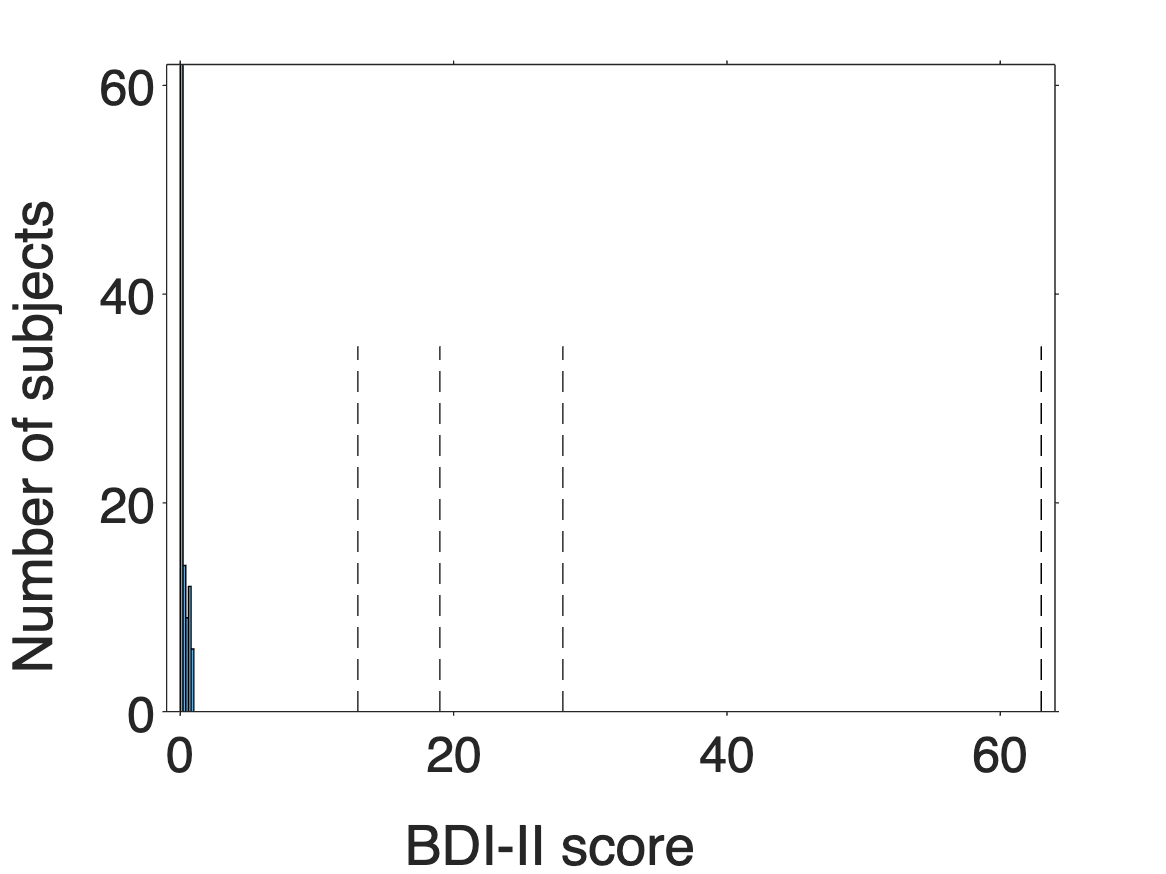

close all
histogram(BDI); hold on
set(gca,'fontsize',18,'tickdir','out')
plot([13 13],[0 35],'k--')
plot([19 19],[0 35],'k--')
plot([28 28],[0 35],'k--')
plot([63 63],[0 35],'k--')
xlim([-1 64])
xlabel('BDI-II score')
ylabel('Number of subjects')


%%
mdl_BDI_concentration = fitlm(tbl, 'BDI_concentration ~ BDI_anhedonia');
mdl_BDI_anhedonia = fitlm(tbl, 'BDI_anhedonia ~ BDI_concentration');

BDI_concentration_resid = mdl_BDI_concentration.Residuals.Raw;
BDI_anhedonia_resid = mdl_BDI_anhedonia.Residuals.Raw;

%%

tbl_tall = table([MSE_low; MSE_high], [false(size(MSE_low)); true(size(MSE_high))], ...
            normalize([BDI; BDI]), ...
            normalize([BDI_anhedonia; BDI_anhedonia]), ...
            normalize([BDI_concentration; BDI_concentration]), [subj; subj], ...
            'VariableNames', ...
           {'MSE','high_incentive','BDI','BDI_anhedonia','BDI_concentration','subj'});

clc




%%
clc
mdl_anhed_conc = fitlme(tbl_tall, ['MSE ~ high_incentive*BDI_anhedonia*BDI_concentration - ' ...
                                         'BDI_anhedonia:BDI_concentration - ' ...
                                         'high_incentive:BDI_anhedonia:BDI_concentration + ' ...
                                         '(BDI_anhedonia - 1|subj) + (BDI_concentration - 1|subj) + (1|subj)'])

mdl_anhed_conc = Linear mixed-effects model fit by ML

Model information:
    Number of observations             206
    Fixed effects coefficients           6
    Random effects coefficients        309
    Covariance parameters                4

Formula:
    MSE ~ 1 + high_incentive*BDI_anhedonia + high_incentive*BDI_concentration + (BDI_anhedonia | subj) + (BDI_concentration | subj) + (1 | subj)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    2129.7    2163    -1054.9          2109.7  

Fixed effects coefficients (95% CIs):
    Name                                          Estimate    SE        tStat      DF     pValue        Lower      Upper   
    {'(Intercept)'                       }         92.165     5.8404     15.781    200    5.6532e-37     80.649      103.68
    {'high_incentive_1'                  }        -6.6278     2.8658    -2.3127    200      0.021754    -12.

## plot that bad boy

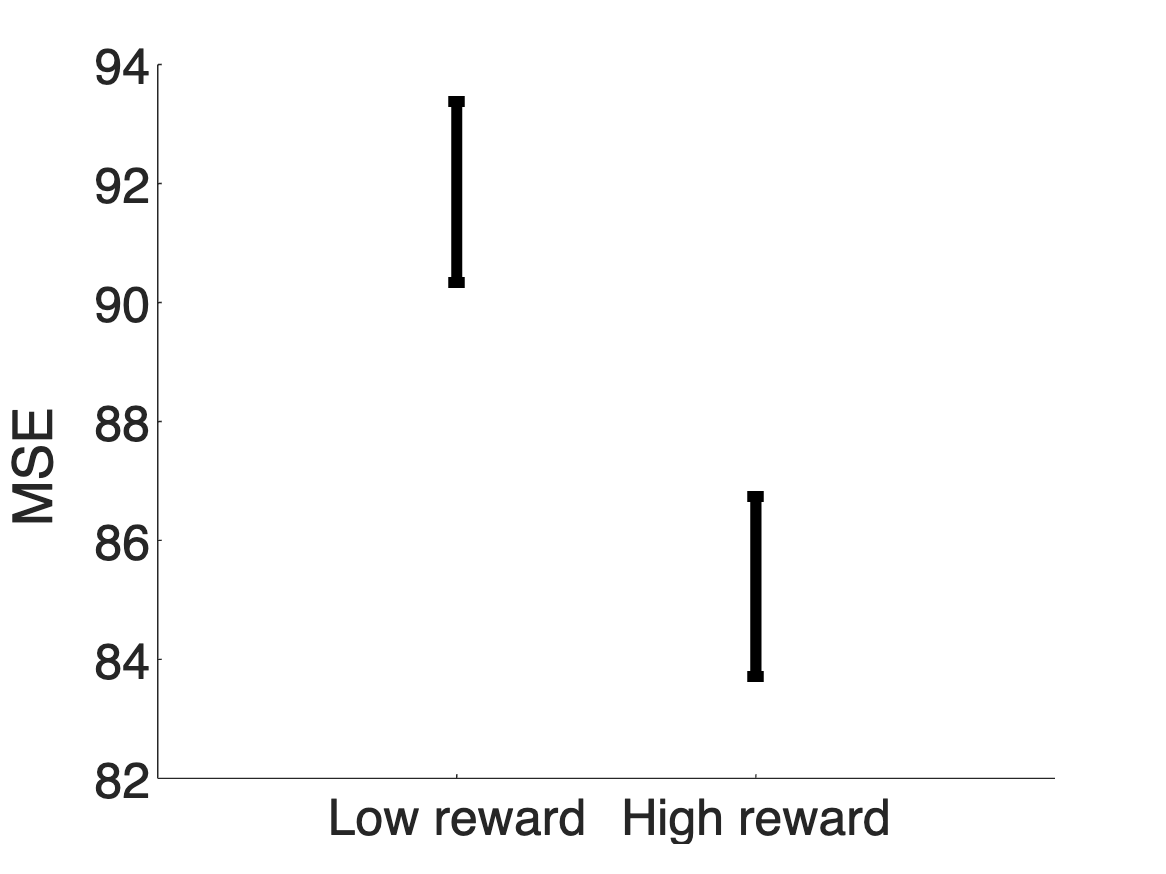

figure; hold on
wse_all = wse([MSE_low MSE_high]);
errorbar(1, nanmean(MSE_low), wse_all(1), 'k', 'linewidth', 4);
errorbar(2, nanmean(MSE_high), wse_all(1), 'k', 'linewidth', 4);
xlim([0 3])
set(gca,'xtick',1:2,'xticklabel',{'Low reward','High reward'})
set(gca,'fontsize',18)
ylabel('MSE')


clc
mdl_all = fitlme(tbl_tall, 'MSE ~ high_incentive + (1|subj)')

mdl_all = Linear mixed-effects model fit by ML

Model information:
    Number of observations             206
    Fixed effects coefficients           2
    Random effects coefficients        103
    Covariance parameters                2

Formula:
    MSE ~ 1 + high_incentive + (1 | subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2149.3    2162.6    -1070.6          2141.3  

Fixed effects coefficients (95% CIs):
    Name                        Estimate    SE        tStat      DF     pValue        Lower     Upper   
    {'(Intercept)'     }         91.856      6.336     14.497    204    3.3214e-33    79.364      104.35
    {'high_incentive_1'}        -6.6278     3.0187    -2.1956    204      0.029251    -12.58    -0.67588

Random effects covariance parameters (95% CIs):
Group: subj (103 Levels)
    Name1                  Name2                  Type  

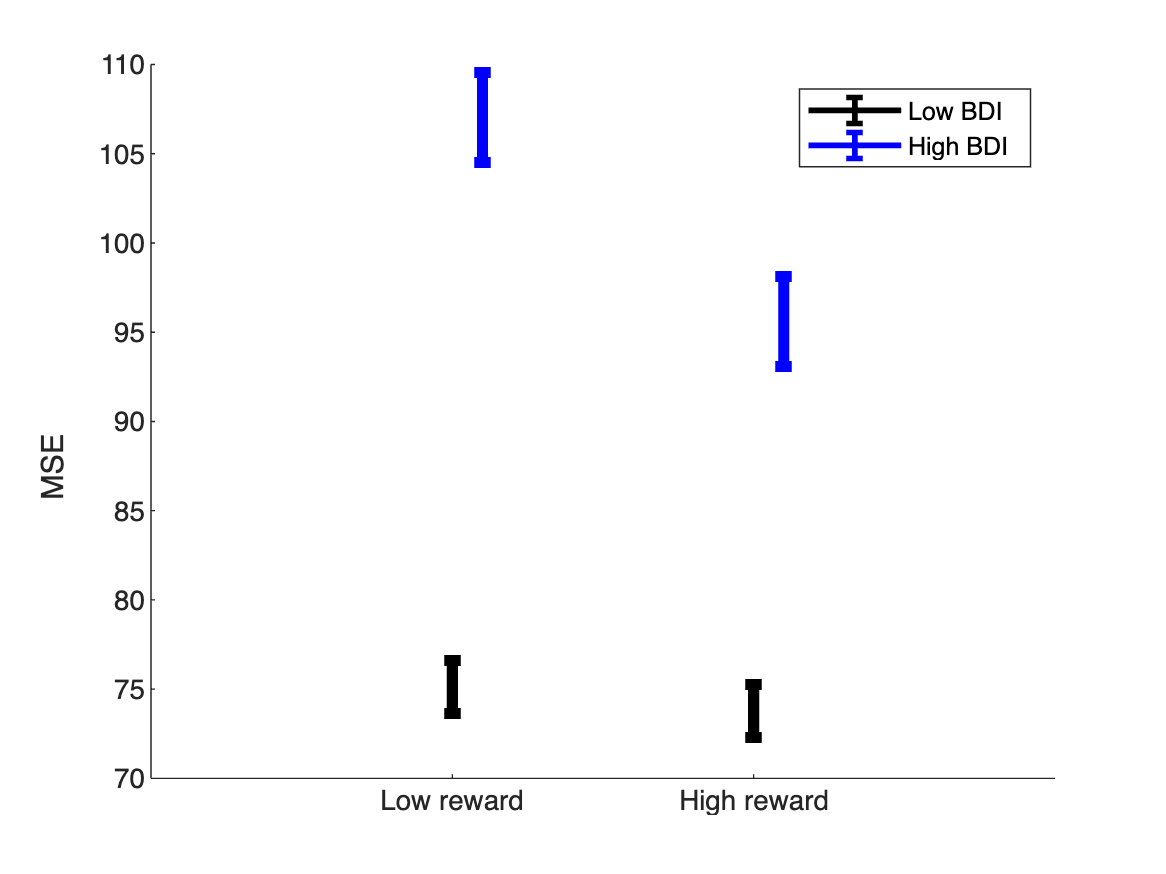

%%


figure; hold on
perf_low_BDI_low = MSE_low(BDI_low);
perf_low_BDI_high = MSE_low(BDI_high);
wse_BDI_low = wse([MSE_low(BDI_low) MSE_high(BDI_low)]);
wse_BDI_high = wse([MSE_low(BDI_high) MSE_high(BDI_high)]);

perf_high_BDI_low = MSE_high(BDI_low);
perf_high_BDI_high = MSE_high(BDI_high);
t(1) = errorbar(1, nanmean(perf_low_BDI_low), wse_BDI_low(1),'k','linewidth',4);
t(2) = errorbar(1.1, nanmean(perf_low_BDI_high), wse_BDI_high(1),'b','linewidth',4);

errorbar(2, nanmean(perf_high_BDI_low), wse_BDI_low(2),'k','linewidth',4)
errorbar(2.1, nanmean(perf_high_BDI_high), wse_BDI_high(2),'b','linewidth',4)
xlim([0 3])
set(gca,'xtick',1:2,'xticklabel',{'Low reward','High reward'}, 'fontsize', 10)
ylabel('MSE')
legend(t,{'Low BDI','High BDI'})

hold off;


% saveas(gcf, 'Bilal_Overall_MSE_vs_Reward.png');

subj = {};
bonus = [];
for s = 1:length(data3.NJ)
    subj = [subj; data3.NJ(s).ID];
    bonus = [bonus; data3.NJ(s).bonus];
end
tbl = table(subj, bonus);
% writetable(tbl, '/Users/brockada/Desktop/Gershman_Lab/anhedonia_numerosity_judgment-main/raw_data/exp2/bonus/bonus_brock.csv', 'WriteVariableNames',0)

## **Brock Data Cleaning + Outlier Detection**

% Creating Unique numeric IDs (Subject values)
IDs = {data.NJ.ID};

% Create a mapping 
[uniqueIDs, ~, idx] = unique(IDs, 'stable'); 

% Assign a new field "subject" with sequential integers
for i = 1:length(data.NJ)
    data.NJ(i).subject = idx(i);
end

% Define the mapping of old field names to new field names
rename_fields = {'avg_true_stim', 'avg_stim'; 
                 'true_stim', 'stimulus';
                 'cond', 'incentive';
                 'est_stim', 'estimate'};

% Loop through each field renaming pair
for i = 1:size(rename_fields, 1)
    oldField = rename_fields{i, 1};
    newField = rename_fields{i, 2};
    
    % Iterate over all elements in data.NJ (array of structures)
    for j = 1:numel(data.NJ)
        if isfield(data.NJ, oldField)
            data.NJ(j).(newField) = data.NJ(j).(oldField); % Copy old field to new field
        end
    end
    
    % Remove the old field (only once since rmfield operates on the whole struct array)
    if isfield(data.NJ, oldField)
        data.NJ = rmfield(data.NJ, oldField);
    end
end


% Define the trial sequence: 120x1 double (1-40 repeated 3 times)
trial_sequence = repmat((1:40)', 3, 1);

% Iterate through each row in data.NJ
for i = 1:length(data.NJ)
    data.NJ(i).trial = trial_sequence; 
end

threshold_trials = 0.05;   % max allowed fraction of bad/outlier trials per subject

allNJ = data.NJ;
numSubj = numel(allNJ);

cleanNJ = struct([]);      % hold only the kept+trimmed subjects
cnt     = 0;

for i = 1:numSubj
    subj = allNJ(i);
    
    % identify bad trials
    outlier_bad = subj.estimate < min(subj.stimulus) | subj.estimate > max(subj.stimulus);
    outlier_bad = outlier_bad | abs(subj.estimate - subj.stimulus) > 40;
    nan_bad = isnan(subj.estimate);
    bad = outlier_bad | nan_bad;

    prop_bad = mean(bad);
    
    % skip subjects with too many outliers (>30 trials)
    if sum(bad) > 30
       continue
    end

    cnt = cnt + 1;
    
    %  scalar fields 
    cleanNJ(cnt).ID                    = subj.ID;
    cleanNJ(cnt).subject               = subj.subject;
    cleanNJ(cnt).cutoff                = subj.cutoff;
    cleanNJ(cnt).nonresponsive_trials  = subj.nonresponsive_trials;
    cleanNJ(cnt).final_bonus           = subj.final_bonus;
    cleanNJ(cnt).task                  = subj.task;
    cleanNJ(cnt).bonus                 = subj.bonus;
    cleanNJ(cnt).survey                = subj.survey;

    % keep stimulus the same
    cleanNJ(cnt).stimulus = subj.stimulus;

    cleanNJ(cnt).estimate = subj.estimate;

    % NaN out all the outlier trials
    cleanNJ(cnt).estimate(bad) = NaN;

    % Create validity mask (1 for valid, 0 for NaN)
    cleanNJ(cnt).valid = ~isnan(cleanNJ(cnt).estimate);

    % everything else stays the same
    cleanNJ(cnt).incentive = subj.incentive;
    cleanNJ(cnt).avg_stim = subj.avg_stim;
    cleanNJ(cnt).block = subj.block;
    cleanNJ(cnt).acc = subj.acc;
    cleanNJ(cnt).r = subj.r;
end

cleanBDI = arrayfun(@(d) sum(d.survey.BDI), cleanNJ(:));
minBDI = min(cleanBDI);
maxBDI = max(cleanBDI);
scaledBDI = (cleanBDI - minBDI) ./ (maxBDI - minBDI);

for i = 1:length(cleanNJ)
    cleanNJ(i).scaled_BDI = scaledBDI(i);
end

BDI_low = cleanBDI < nanmedian(cleanBDI);
BDI_high = cleanBDI >= nanmedian(cleanBDI);


% original (Sam's) RI model
results_RI = fit_models_brock_RI(cleanNJ);

Subject 1
Initial parameter values (x0):
    1.6255   45.2861    6.3497

Initial parameter values (x0):
    1.8223   31.6158    4.8775

Initial parameter values (x0):
    0.5557   27.3423   47.8716

Initial parameter values (x0):
    1.9251    7.8809   48.5258

Initial parameter values (x0):
    1.9096   24.2674   40.0110

Subject 2
Initial parameter values (x0):
    0.2832   21.0870   45.7832

Initial parameter values (x0):
    1.5806   47.9708   32.7848

Initial parameter values (x0):
    0.0713   42.4532   46.6960

Initial parameter values (x0):
    1.3542   37.8842   37.1539

Initial parameter values (x0):
    0.7826   32.7716    8.5595

Subject 3
Initial parameter values (x0):
    1.4087    1.5925   13.8458

Initial parameter values (x0):
    0.0922    4.8571   41.1698

Initial parameter values (x0):
    1.3863   15.8544   47.5074

Initial parameter values (x0):
    0.0688   21.9360   19.0770

Initial parameter values (x0):
    1.5273   39.7570    9.3437

Subject 4
Initial paramet


% BDI "turned off" (BDI_intact = 0)
results_BDI_off = fit_models_brock_BDI_intact(cleanNJ, 0);

Subject 1
Initial parameter values (x0):
    0.1367   21.8152  -16.3073  -23.6946

Initial parameter values (x0):
    1.9085   21.5287   23.0779   13.1207

Initial parameter values (x0):
    0.0148   33.9995   10.2975    7.2564

Initial parameter values (x0):
    1.1042   10.9053   13.6183  -13.5986

Initial parameter values (x0):
    0.7415   44.5430   17.8188   -4.8783

Subject 2
Initial parameter values (x0):
    0.6358   30.4297   20.5098   20.4549

Initial parameter values (x0):
    1.1827   16.6279   17.6532   -2.8801

Initial parameter values (x0):
    1.8079    1.6598    1.6213   10.8249

Initial parameter values (x0):
    0.3585   16.8260  -15.6144   -8.9036

Initial parameter values (x0):
    0.8074   27.4266  -22.5631    2.6366

Subject 3
Initial parameter values (x0):
    0.5494   12.0749  -12.8427  -17.2920

Initial parameter values (x0):
    1.9120   46.7794   15.9357   11.4131

Initial parameter values (x0):
    0.3515   18.0177  -15.5605  -24.9401

Initial parameter val


% full BDI model (BDI_intact = 1)
results_BDI_full = fit_models_brock_BDI_intact(cleanNJ, 1);

Subject 1
Initial parameter values (x0):
    0.8015   49.7455  -11.9501    8.2662

Initial parameter values (x0):
    1.9276   33.5552  -10.0413    1.5563

Initial parameter values (x0):
    0.0030   44.1860   -4.7808   -9.9397

Initial parameter values (x0):
    1.9003   23.0311  -10.6176  -20.7687

Initial parameter values (x0):
    1.1639    7.6537  -21.3453    4.0282

Subject 2
Initial parameter values (x0):
    0.5738   18.0952   11.2412   17.9156

Initial parameter values (x0):
    0.6956   48.0835   22.6785  -14.6981

Initial parameter values (x0):
    1.5358   30.7745   20.9461    5.1269

Initial parameter values (x0):
    1.4037   37.1810   -5.7449  -12.4248

Initial parameter values (x0):
    0.0736   23.6048    7.2536  -11.0515

Subject 3
Initial parameter values (x0):
    1.0353   12.2831  -10.1246    7.5237

Initial parameter values (x0):
    1.7820   43.0520  -14.5042   -5.0453

Initial parameter values (x0):
    1.7750   12.8261   23.3401    5.9579

Initial parameter val

## **Table Building (STAN)**

function write_stan_data(data_struct, filename)
    fid = fopen(filename, 'w');
    
    % Get all field names
    fields = fieldnames(data_struct);
    
    % Loop through each field and write it to the file
    for i = 1:length(fields)
        field_name = fields{i};
        field_data = data_struct.(field_name);
        
        % Write different formats based on data type
        if isscalar(field_data)
            % Scalar - handle different data types
            if islogical(field_data)
                fprintf(fid, '%s <- %d\n', field_name, double(field_data));
            elseif isinteger(field_data)
                fprintf(fid, '%s <- %d\n', field_name, field_data);
            else
                fprintf(fid, '%s <- %g\n', field_name, field_data);
            end
        elseif isvector(field_data)
            % Vector - handle different data types
            fprintf(fid, '%s <- c(', field_name);
            
            % Check if it's logical and convert to numeric if needed
            if islogical(field_data)
                field_data = double(field_data);
            end
            
            % Check if it's an integer or float vector for formatting
            if all(mod(field_data, 1) == 0)
                % Integer values
                fprintf(fid, '%d,', field_data(1:end-1));
                fprintf(fid, '%d)\n', field_data(end));
            else
                % Float values
                fprintf(fid, '%g,', field_data(1:end-1));
                fprintf(fid, '%g)\n', field_data(end));
            end
        else
            % Matrix - R uses column-major order
            fprintf(fid, '%s <- structure(c(', field_name);
            
            % Special handling for valid mask - ensure it's numeric
            if strcmp(field_name, 'valid') && islogical(field_data)
                field_data = double(field_data);
            end
            
            % Flatten the matrix in column-major order (transpose for MATLAB)
            flat_data = field_data';
            flat_data = flat_data(:)';
            
            % Check if it contains only integers
            if all(mod(flat_data, 1) == 0)
                % Integer matrix
                fprintf(fid, '%d,', flat_data(1:end-1));
                fprintf(fid, '%d), ', flat_data(end));
            else
                % Float matrix
                fprintf(fid, '%g,', flat_data(1:end-1));
                fprintf(fid, '%g), ', flat_data(end));
            end
            
            % Write the dimensions
            fprintf(fid, '.Dim = c(%d, %d))\n', size(field_data, 2), size(field_data, 1));
        end
    end
    
    % Close the file
    fclose(fid);
    
    fprintf('Stan data written to %s\n', filename);
end

numSubj = numel(cleanNJ);
trialsPerSub = numel(cleanNJ(1).stimulus);

% Initialize the structure
stan_input = struct();

% Initialize arrays to hold all data
all_stimulus = [];
all_estimate = [];
all_incentive = [];
all_avg_stim = [];
all_valid = [];

% Collect data from all subjects
for i = 1:numSubj
    all_stimulus = [all_stimulus; cleanNJ(i).stimulus'];
    all_estimate = [all_estimate; cleanNJ(i).estimate'];
    all_incentive = [all_incentive; cleanNJ(i).incentive'];
    all_avg_stim = [all_avg_stim; cleanNJ(i).avg_stim'];
    all_valid = [all_valid; cleanNJ(i).valid'];
end

all_estimate_clean = all_estimate;
all_estimate_clean(isnan(all_estimate_clean)) = 0;  %NaN values = 0

stan_input.Nsubject = numSubj;
stan_input.Ntrial = trialsPerSub;
stan_input.stimulus = all_stimulus;
stan_input.estimate = all_estimate_clean;
stan_input.incentive = all_incentive;
stan_input.avg_stim = all_avg_stim;
stan_input.valid = all_valid;

stan_input.subject_id = [cleanNJ.subject]';
stan_input.scaledBDI = [cleanNJ.scaled_BDI]';

% save_dir = '/MATLAB Drive/Gershman_Lab/';
% write_stan_data(stan_input, [save_dir 'stan_input_full.R']);

## Simulations (RI Model)

data_synth_RI = cleanNJ;
latents = results_RI.latents;
assert(numel(latents)==numel(cleanNJ),'latents/cleanNJ mismatch');

for i = 1:numel(latents)
  mu      = latents(i).log_estimate;
  sig2    = latents(i).log_var;
  draw    = mu + sqrt(sig2).*randn(size(mu));
  synth   = round(exp(draw));

  stim    = cleanNJ(i).stimulus;
  bad     = ~cleanNJ(i).valid ... 
           | synth<min(stim) ...              
           | synth>max(stim) ...
           | abs(synth-stim)>40;               
  synth(bad)=NaN;

  data_synth_RI(i).estimate = synth;
end

## Simulation (BDI Off)

data_synth_BDI_off = cleanNJ;
latents = results_BDI_off.latents;
assert(numel(latents)==numel(cleanNJ),'latents/cleanNJ mismatch');

for i = 1:numel(latents)
  mu      = latents(i).log_estimate;
  sig2    = latents(i).log_var;
  draw    = mu + sqrt(sig2).*randn(size(mu));
  synth   = round(exp(draw));

  stim    = cleanNJ(i).stimulus;
  bad     = ~cleanNJ(i).valid ... 
           | synth<min(stim) ...              
           | synth>max(stim) ...
           | abs(synth-stim)>40;               
  synth(bad)=NaN;

  data_synth_BDI_off(i).estimate = synth;
end


## Simulation (BDI Full)

data_synth_BDI_full = cleanNJ;
latents = results_BDI_full.latents;
assert(numel(latents)==numel(cleanNJ),'latents/cleanNJ mismatch');

for i = 1:numel(latents)
  mu      = latents(i).log_estimate;
  sig2    = latents(i).log_var;
  draw    = mu + sqrt(sig2).*randn(size(mu));
  synth   = round(exp(draw));

  stim    = cleanNJ(i).stimulus;
  bad     = ~cleanNJ(i).valid ... 
           | synth<min(stim) ...              
           | synth>max(stim) ...
           | abs(synth-stim)>40;               
  synth(bad)=NaN;

  data_synth_BDI_full(i).estimate = synth;
end


results_synth_RI = fit_models_brock_RI(data_synth_RI);

Subject 1
Initial parameter values (x0):
    0.6759    1.9785   20.0376

Initial parameter values (x0):
    1.6849   22.8222   40.0583

Initial parameter values (x0):
    0.7534   27.9192   20.1453

Initial parameter values (x0):
    1.4783   39.5833   32.6254

Initial parameter values (x0):
    1.9669   49.1367   22.3826

Subject 2
Initial parameter values (x0):
    1.9559   42.2917    1.7823

Initial parameter values (x0):
    0.8455   47.8981   40.4491

Initial parameter values (x0):
    0.5976   11.2989    8.9301

Initial parameter values (x0):
    0.7725   12.2733   24.8941

Initial parameter values (x0):
    0.8127   39.7402   28.1771

Subject 3
Initial parameter values (x0):
    1.2694    6.4867   21.1406

Initial parameter values (x0):
    0.8228   11.7225   16.7503

Initial parameter values (x0):
    1.2104   25.0052   40.9376

Initial parameter values (x0):
    0.4747   18.0746   23.0572

Initial parameter values (x0):
    1.4801   33.1985    5.2688

Subject 4
Initial paramet

results_synth_BDI_off = fit_models_brock_BDI_intact(data_synth_BDI_off, 0) 

Subject 1
Initial parameter values (x0):
    0.8778    0.2323   17.8774   -3.4642

Initial parameter values (x0):
    1.4232   18.0015   14.0719    5.2524

Initial parameter values (x0):
    1.0835   30.8513  -18.1227    9.0900

Initial parameter values (x0):
    0.9662   36.7203   -6.2192   -0.2143

Initial parameter values (x0):
    1.4480   49.3775   16.6036   24.8185

Subject 2
Initial parameter values (x0):
    1.9437   30.4764  -12.5097   22.9406

Initial parameter values (x0):
    1.9087   33.0869   -4.5552  -20.2976

Initial parameter values (x0):
    0.2091   48.0575   21.3444   17.4984

Initial parameter values (x0):
    0.0295   24.2494    3.1642   10.5621

Initial parameter values (x0):
    0.6231   32.1414   -3.9000    6.6085

Subject 3
Initial parameter values (x0):
    0.4834   38.1679   -0.9962   -7.8757

Initial parameter values (x0):
    0.2649   31.6116   -2.1061  -23.2884

Initial parameter values (x0):
    1.0237    0.1323  -24.1691    4.6782

Initial parameter val

results_synth_BDI_off = struct with fields:
          K: 4
      param: [1x4 struct]
     likfun: @(x,data)likfun_RI_inline(x,data,BDI_intact)
    logpost: [-3.6025e+04 -1.6023e+04 -1.2962e+04 -1.0955e+04 -1.5990e+04 -4.6026e+04 -3.2025e+04 -1.3960e+04 -1.6011e+04 -1.2968e+04 -2.2975e+04 -2.2002e+04 -1.4941e+04 -1.0943e+04 -2.0011e+04 -3.2001e+04 -1.9003e+04 -8.9885e+03 ... ] (1x102 double)
     loglik: [-3.6025e+04 -1.6023e+04 -1.2962e+04 -1.0955e+04 -1.5990e+04 -4.6026e+04 -3.2025e+04 -1.3960e+04 -1.6011e+04 -1.2968e+04 -2.2975e+04 -2.2002e+04 -1.4941e+04 -1.0943e+04 -2.0011e+04 -3.2001e+04 -1.9003e+04 -8.9885e+03 ... ] (1x102 double)
          x: [102x4 double]
          H: {1x102 cell}
        bic: [102x1 double]
        aic: [102x1 double]
    latents: [1x102 struct]


results_synth_BDI_full = fit_models_brock_BDI_intact(data_synth_BDI_full, 1) 

Subject 1
Initial parameter values (x0):
    0.0628   24.4957  -14.1520  -11.8453

Initial parameter values (x0):
    0.1078    0.7809   12.7388    6.1537

Initial parameter values (x0):
    1.0663   41.1932  -12.1194   14.8826

Initial parameter values (x0):
    1.3955    0.5232   22.5325   -5.0246

Initial parameter values (x0):
    0.0798   20.9227   -6.8640    8.4173

Subject 2
Initial parameter values (x0):
    1.0769   45.4916   16.1352  -16.9718

Initial parameter values (x0):
    0.6068    7.8919   -7.0467  -22.0341

Initial parameter values (x0):
    1.5150   49.8315    9.9863   -9.2951

Initial parameter values (x0):
    0.6817   41.4624  -15.0959  -11.3265

Initial parameter values (x0):
    0.7731   29.9818  -11.1138  -24.8601

Subject 3
Initial parameter values (x0):
    1.6022    0.3761  -14.9637    1.6633

Initial parameter values (x0):
    0.4136   48.1469    0.2996  -22.3488

Initial parameter values (x0):
    1.8891   15.2681   -0.5434    3.2123

Initial parameter val

results_synth_BDI_full = struct with fields:
          K: 4
      param: [1x4 struct]
     likfun: @(x,data)likfun_RI_inline(x,data,BDI_intact)
    logpost: [-3.7025e+04 -2.0010e+04 -1.0970e+04 -7.9268e+03 -1.0978e+04 -4.4018e+04 -3.2036e+04 -8.9519e+03 -2.5006e+04 -6.9602e+03 -2.6990e+04 -2.0021e+04 -1.4949e+04 -4.9438e+03 -1.4038e+04 -3.2012e+04 -1.7009e+04 -1.0963e+04 ... ] (1x102 double)
     loglik: [-3.7025e+04 -2.0010e+04 -1.0970e+04 -7.9268e+03 -1.0978e+04 -4.4018e+04 -3.2036e+04 -8.9519e+03 -2.5006e+04 -6.9602e+03 -2.6990e+04 -2.0021e+04 -1.4949e+04 -4.9438e+03 -1.4038e+04 -3.2012e+04 -1.7009e+04 -1.0963e+04 ... ] (1x102 double)
          x: [102x4 double]
          H: {1x102 cell}
        bic: [102x1 double]
        aic: [102x1 double]
    latents: [1x102 struct]


% Comparing latents
function summary_stats = compute_latent_summaries(latents_struct)
    num_subjects = numel(latents_struct);
    
    % Initialize the summary structure
    summary_stats = struct('mean_log_estimate', zeros(num_subjects, 1), ...
                          'mean_confidence', zeros(num_subjects, 1), ...
                          'mean_log_var', zeros(num_subjects, 1), ...
                          'median_log_estimate', zeros(num_subjects, 1), ...
                          'median_confidence', zeros(num_subjects, 1), ...
                          'median_log_var', zeros(num_subjects, 1), ...
                          'std_log_estimate', zeros(num_subjects, 1), ...
                          'std_confidence', zeros(num_subjects, 1), ...
                          'std_log_var', zeros(num_subjects, 1), ...
                          'min_log_var', zeros(num_subjects, 1), ...
                          'max_log_var', zeros(num_subjects, 1));
    
    % Compute summary statistics for each subject
    for i = 1:num_subjects
        % Extract the latent variables for this subject
        log_estimate = latents_struct(i).log_estimate;
        confidence = latents_struct(i).confidence;
        log_var = latents_struct(i).log_var;
        
        % Compute means
        summary_stats.mean_log_estimate(i) = mean(log_estimate, 'omitnan');
        summary_stats.mean_confidence(i) = mean(confidence, 'omitnan');
        summary_stats.mean_log_var(i) = mean(log_var, 'omitnan');
        
        % Compute medians
        summary_stats.median_log_estimate(i) = median(log_estimate, 'omitnan');
        summary_stats.median_confidence(i) = median(confidence, 'omitnan');
        summary_stats.median_log_var(i) = median(log_var, 'omitnan');
        
        % Compute standard deviations
        summary_stats.std_log_estimate(i) = std(log_estimate, 'omitnan');
        summary_stats.std_confidence(i) = std(confidence, 'omitnan');
        summary_stats.std_log_var(i) = std(log_var, 'omitnan');
        
        % Min and max of log_var (useful to check for extremely large values)
        summary_stats.min_log_var(i) = min(log_var, [], 'omitnan');
        summary_stats.max_log_var(i) = max(log_var, [], 'omitnan');
    end
end

summary_stats_RI = compute_latent_summaries(results_RI.latents);
summary_stats_synth_RI = compute_latent_summaries(results_synth_RI.latents);

## MSE Simulations vs. Real Data Scatterplots

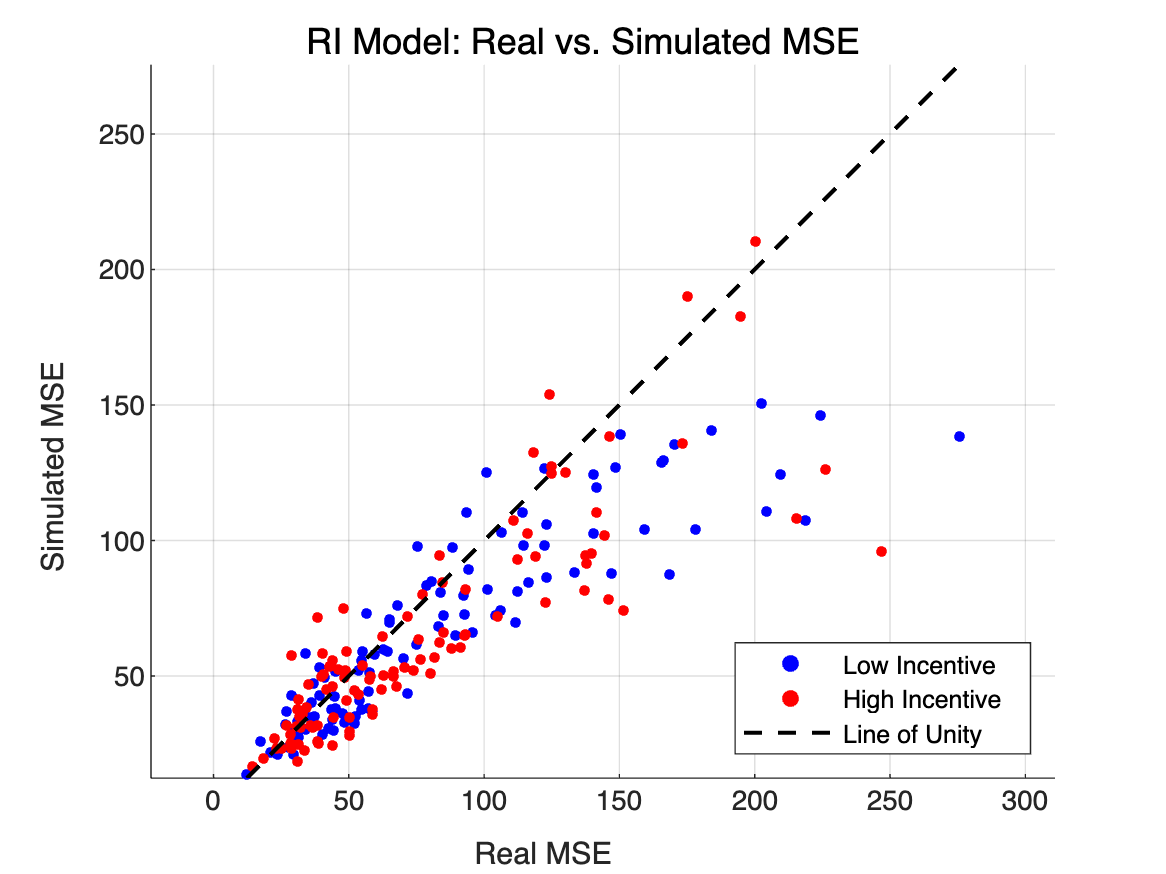

% arrays for MSE (real and simulated) for each subject and condition
numSubjects = numel(cleanNJ);
MSE_real_low = zeros(numSubjects, 1); % Low incentive
MSE_real_high = zeros(numSubjects, 1); % High incentive
MSE_sim_RI_low = zeros(numSubjects, 1);
MSE_sim_RI_high = zeros(numSubjects, 1);
MSE_sim_BDI_off_low = zeros(numSubjects, 1);
MSE_sim_BDI_off_high = zeros(numSubjects, 1);
MSE_sim_BDI_full_low = zeros(numSubjects, 1);
MSE_sim_BDI_full_high = zeros(numSubjects, 1);

% Loop over subjects to compute the MSEs for each condition
for i = 1:numSubjects
    % Get the true stimulus for subject i
    real_stim = cleanNJ(i).stimulus;
    % Get the estimates and handle outliers
    real_est = cleanNJ(i).estimate;
    real_est(real_est > 100) = NaN; % excluding responses above 100
    % Get the incentive condition (convert to binary indicator)
    raw_cond = cleanNJ(i).incentive;
    cond_low = (raw_cond == 0.4); % Low incentive (0.4)
    cond_high = (raw_cond == 2); % High incentive (2)
    % Compute real MSE for each condition
    MSE_real_low(i) = mean((real_est(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_real_high(i) = mean((real_est(cond_high) - real_stim(cond_high)).^2, 'omitnan');
    % Compute simulated MSE for each model and condition
    MSE_sim_RI_low(i) = mean((data_synth_RI(i).estimate(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_sim_RI_high(i) = mean((data_synth_RI(i).estimate(cond_high) - real_stim(cond_high)).^2, 'omitnan');
    MSE_sim_BDI_off_low(i) = mean((data_synth_BDI_off(i).estimate(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_sim_BDI_off_high(i) = mean((data_synth_BDI_off(i).estimate(cond_high) - real_stim(cond_high)).^2, 'omitnan');
    MSE_sim_BDI_full_low(i) = mean((data_synth_BDI_full(i).estimate(cond_low) - real_stim(cond_low)).^2, 'omitnan');
    MSE_sim_BDI_full_high(i) = mean((data_synth_BDI_full(i).estimate(cond_high) - real_stim(cond_high)).^2, 'omitnan');
end

% --- Plot for the Original RI Model ---
figure;
hold on;
h1 = scatter(MSE_real_low, MSE_sim_RI_low, 15, 'b', 'filled', 'o'); % Blue for low incentive
h2 = scatter(MSE_real_high, MSE_sim_RI_high, 15, 'r', 'filled', 'o'); % Red for high incentive

% Create line of unity manually
all_MSE_real = [MSE_real_low; MSE_real_high];
all_MSE_sim_RI = [MSE_sim_RI_low; MSE_sim_RI_high];
min_val = min([all_MSE_real; all_MSE_sim_RI]);
max_val = max([all_MSE_real; all_MSE_sim_RI]);
h3 = plot([min_val, max_val], [min_val, max_val], 'k--', 'LineWidth', 1.5);

hold off;
xlabel('Real MSE');
ylabel('Simulated MSE');
sgtitle('RI Model: Real vs. Simulated MSE');

% Set equal axis limits for square plot
axis_min = min([all_MSE_real; all_MSE_sim_RI]);
axis_max = max([all_MSE_real; all_MSE_sim_RI]);
xlim([axis_min, axis_max]);
ylim([axis_min, axis_max]);
axis equal;

legend([h1, h2, h3], {'Low Incentive', 'High Incentive', 'Line of Unity'}, 'Location', 'southeast');
grid on;

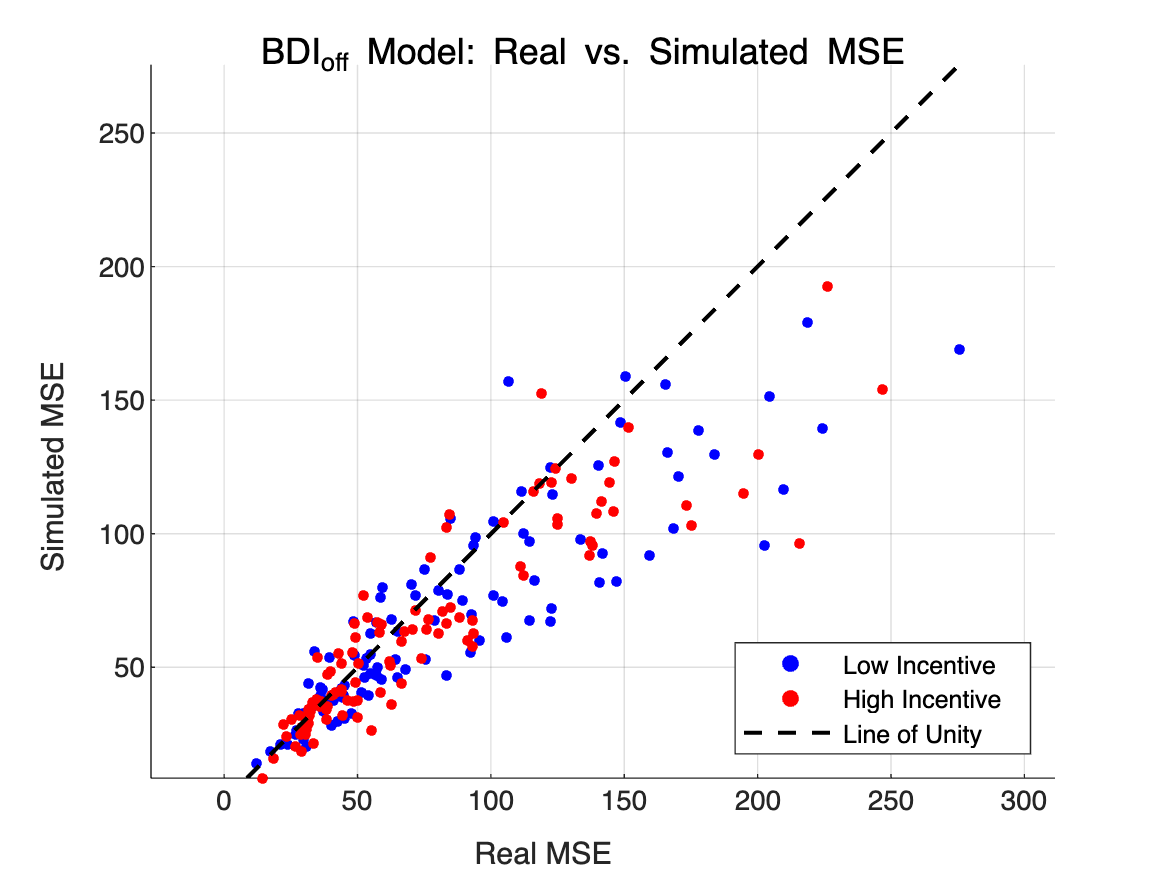


% --- Plot for the BDI_off Model ---
figure;
hold on;
h1 = scatter(MSE_real_low, MSE_sim_BDI_off_low, 15, 'b', 'filled', 'o'); % Blue for low incentive
h2 = scatter(MSE_real_high, MSE_sim_BDI_off_high, 15, 'r', 'filled', 'o'); % Red for high incentive

% Create line of unity manually
all_MSE_sim_BDI_off = [MSE_sim_BDI_off_low; MSE_sim_BDI_off_high];
min_val = min([all_MSE_real; all_MSE_sim_BDI_off]);
max_val = max([all_MSE_real; all_MSE_sim_BDI_off]);
h3 = plot([min_val, max_val], [min_val, max_val], 'k--', 'LineWidth', 1.5);

hold off;
xlabel('Real MSE');
ylabel('Simulated MSE');
sgtitle('BDI_{off} Model: Real vs. Simulated MSE');

% Set equal axis limits for square plot
axis_min = min([all_MSE_real; all_MSE_sim_BDI_off]);
axis_max = max([all_MSE_real; all_MSE_sim_BDI_off]);
xlim([axis_min, axis_max]);
ylim([axis_min, axis_max]);
axis equal;

legend([h1, h2, h3], {'Low Incentive', 'High Incentive', 'Line of Unity'}, 'Location', 'southeast');
grid on;

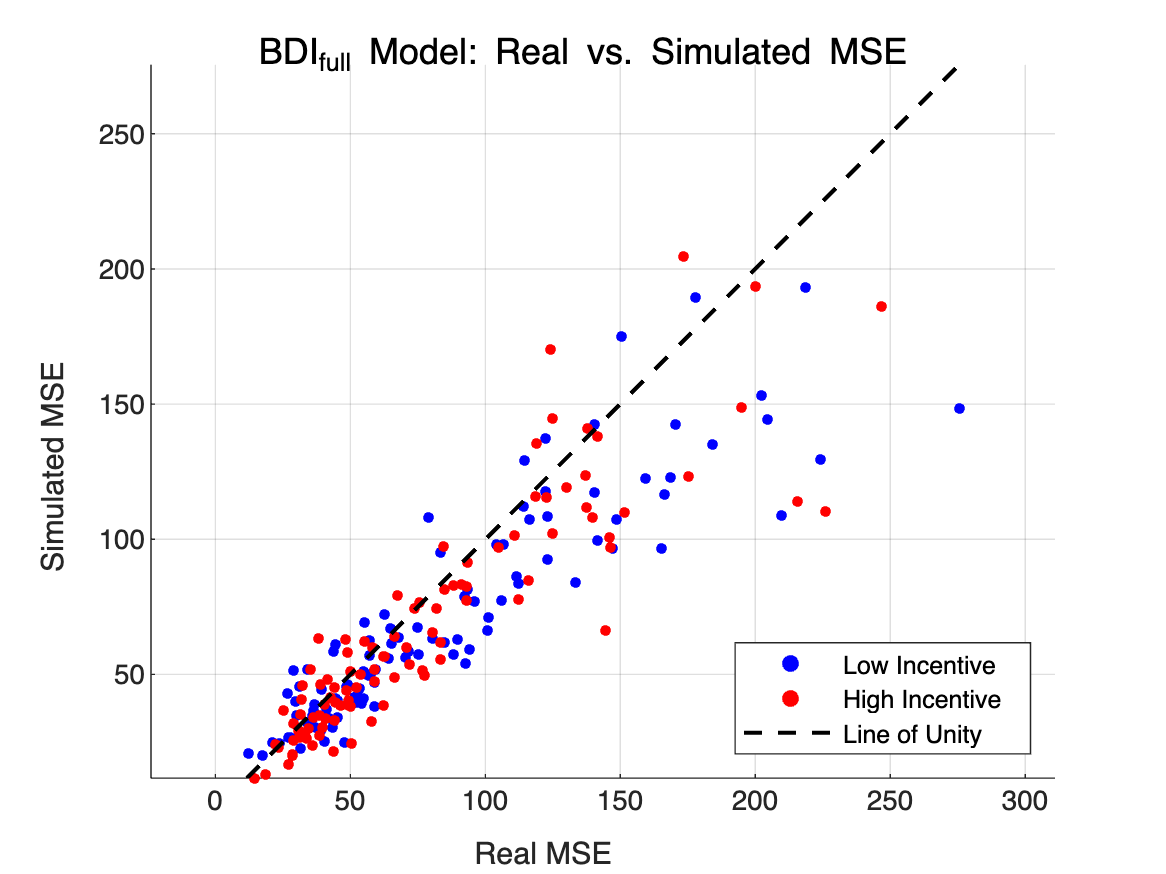


% --- Plot for the BDI_full Model ---
figure;
hold on;
h1 = scatter(MSE_real_low, MSE_sim_BDI_full_low, 15, 'b', 'filled', 'o'); % Blue for low incentive
h2 = scatter(MSE_real_high, MSE_sim_BDI_full_high, 15, 'r', 'filled', 'o'); % Red for high incentive

% Create line of unity manually
all_MSE_sim_BDI_full = [MSE_sim_BDI_full_low; MSE_sim_BDI_full_high];
min_val = min([all_MSE_real; all_MSE_sim_BDI_full]);
max_val = max([all_MSE_real; all_MSE_sim_BDI_full]);
h3 = plot([min_val, max_val], [min_val, max_val], 'k--', 'LineWidth', 1.5);

hold off;
xlabel('Real MSE');
ylabel('Simulated MSE');
sgtitle('BDI_{full} Model: Real vs. Simulated MSE');

% Set equal axis limits for square plot
axis_min = min([all_MSE_real; all_MSE_sim_BDI_full]);
axis_max = max([all_MSE_real; all_MSE_sim_BDI_full]);
xlim([axis_min, axis_max]);
ylim([axis_min, axis_max]);
axis equal;

legend([h1, h2, h3], {'Low Incentive', 'High Incentive', 'Line of Unity'}, 'Location', 'southeast');
grid on;

## HISTOGRAMS of BEST FIT PARAMS

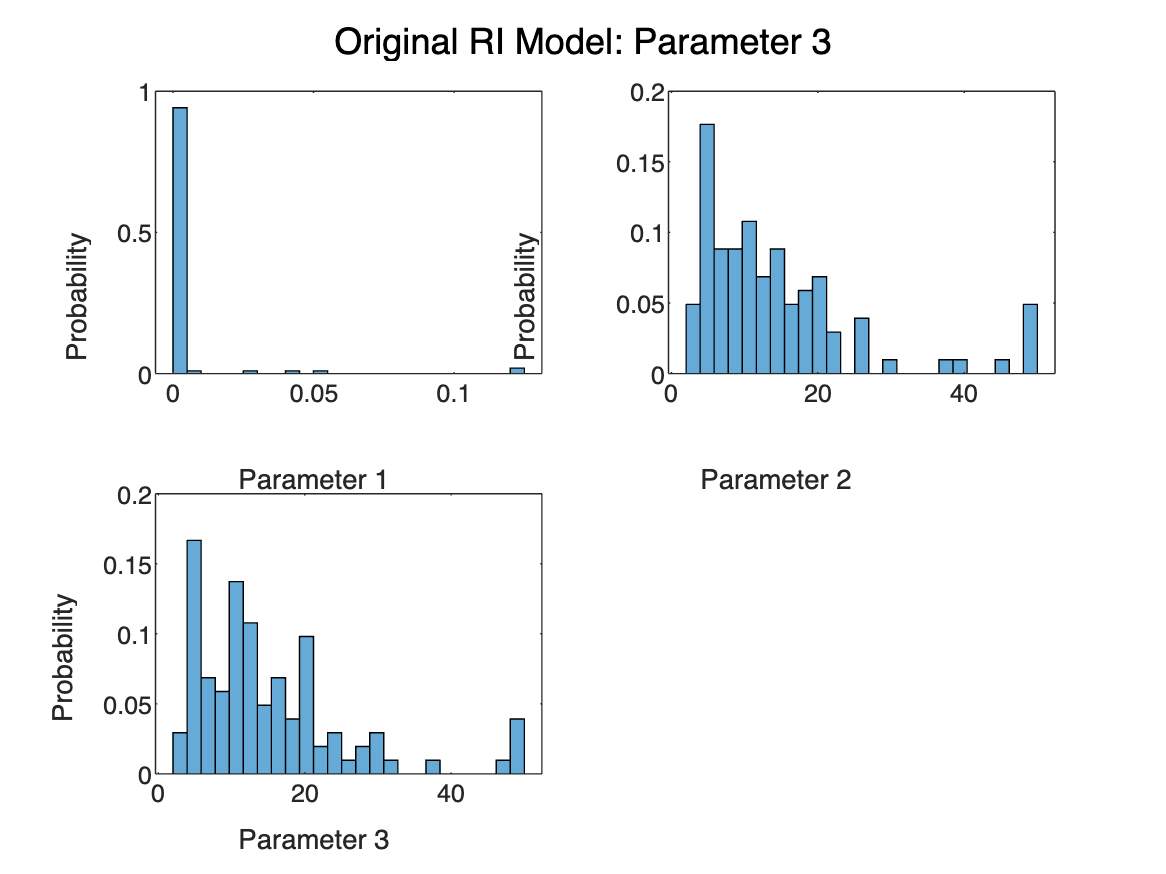

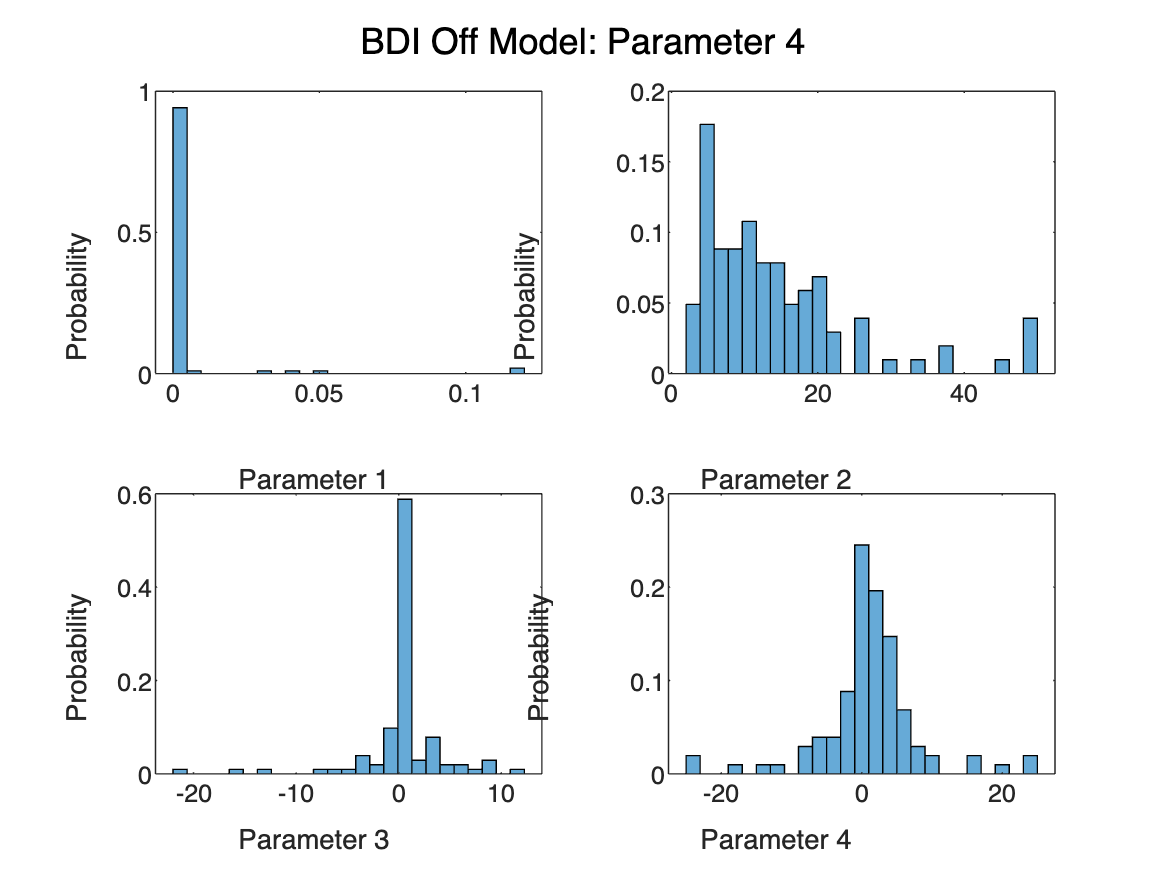

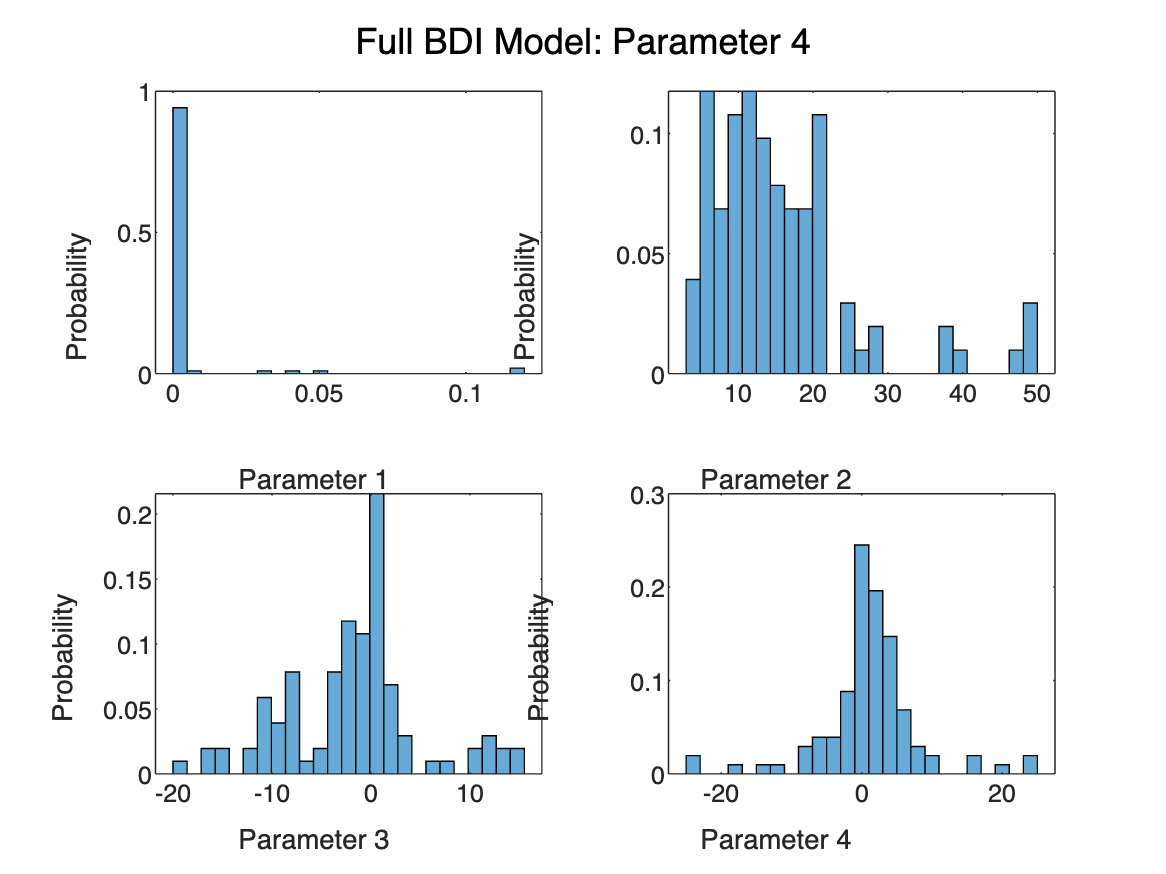

models = {results_RI, results_BDI_off, results_BDI_full};
modelNames = {'Original RI Model', 'BDI Off Model', 'Full BDI Model'};

for m = 1:length(models)
    currResults = models{m};
    numParams = size(currResults.x, 2);
         
    % Create a new figure for this model
    figure('Name', modelNames{m});
    
    % Create subplots for each parameter (arranged in 2 columns)
    for p = 1:numParams
        subplot(ceil(numParams/2), 2, p);  
        histogram(currResults.x(:, p), 'Normalization', 'probability', 'NumBins', 25);
        xlabel(sprintf('Parameter %d', p));
        ylabel('Probability');
        sgtitle(sprintf('%s: Parameter %d', modelNames{m}, p));
    end
end


models = {results_RI, results_BDI_off, results_BDI_full};
modelNames = {'Original RI Model', 'BDI Off Model', 'Full BDI Model'};

for m = 1:length(models)
    currResults = models{m};
    numParams = size(currResults.x, 2);
    fprintf('\n%s:\n', modelNames{m});
    for p = 1:numParams
        paramVals = currResults.x(:, p);
        % Compute the mode using MATLAB's built-in mode function.
        mode_val = mode(paramVals);
        fprintf('  Parameter %d mode: %.4f\n', p, mode_val);
    end
end


Original RI Model:


  Parameter 1 mode: 0.0001
  Parameter 2 mode: 2.7595
  Parameter 3 mode: 2.9595



BDI Off Model:


  Parameter 1 mode: 0.0001
  Parameter 2 mode: 2.7606
  Parameter 3 mode: -21.1802
  Parameter 4 mode: -24.9933



Full BDI Model:


  Parameter 1 mode: 0.0001
  Parameter 2 mode: 3.0814
  Parameter 3 mode: -19.2165
  Parameter 4 mode: -24.9668


## Combined Plots MSE + Fitted Alphas

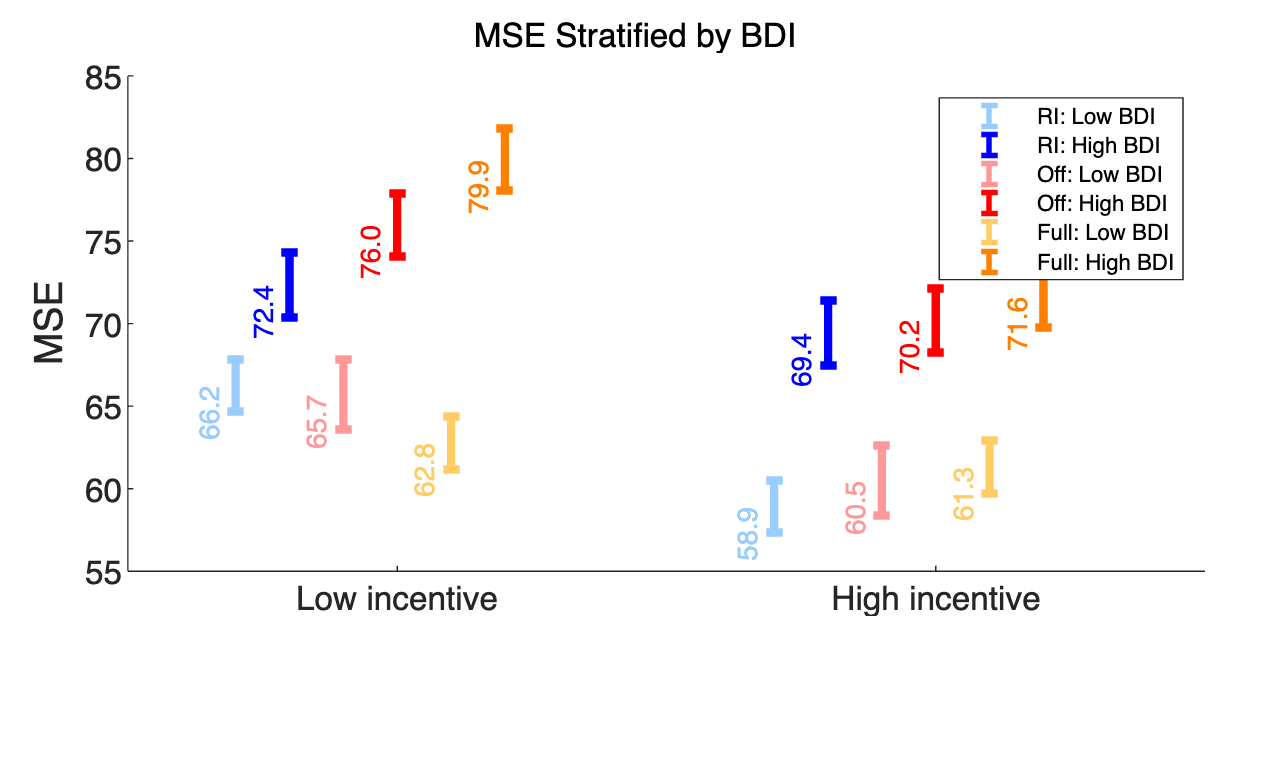

numSubjects   = numel(cleanNJ);
MSE_low_RI    = nan(numSubjects,1);
MSE_high_RI   = nan(numSubjects,1);

for i = 1:numSubjects
    stim      = cleanNJ(i).stimulus;
    synth_est = data_synth_RI(i).estimate;
    cond_low  = cleanNJ(i).incentive == 0.4;
    cond_high = cleanNJ(i).incentive == 2;
    MSE_low_RI(i)  = nanmean((synth_est(cond_low)  - stim(cond_low)).^2);
    MSE_high_RI(i) = nanmean((synth_est(cond_high) - stim(cond_high)).^2);
end

% MSE for BDI_off Model
MSE_low_BDI_off = nan(numSubjects, 1);
MSE_high_BDI_off = nan(numSubjects, 1);

for i = 1:numSubjects
    stim = cleanNJ(i).stimulus;
    synth_est = data_synth_BDI_off(i).estimate;
    cond_low = cleanNJ(i).incentive == 0.4;
    cond_high = cleanNJ(i).incentive == 2;
    MSE_low_BDI_off(i) = nanmean((synth_est(cond_low) - stim(cond_low)).^2);
    MSE_high_BDI_off(i) = nanmean((synth_est(cond_high) - stim(cond_high)).^2);
end

% MSE for BDI Full Model
MSE_low_BDI_full = nan(numSubjects, 1);
MSE_high_BDI_full = nan(numSubjects, 1);

for i = 1:numSubjects
    stim = cleanNJ(i).stimulus;
    synth_est = data_synth_BDI_full(i).estimate;  % Use pre-computed
    cond_low = cleanNJ(i).incentive == 0.4;
    cond_high = cleanNJ(i).incentive == 2;
    MSE_low_BDI_full(i) = nanmean((synth_est(cond_low) - stim(cond_low)).^2);
    MSE_high_BDI_full(i) = nanmean((synth_est(cond_high) - stim(cond_high)).^2);
end

figure('Position', [100, 100, 1000, 600]);
subplot('Position', [0.1, 0.25, 0.85, 0.65]);
hold on

light_blue = [0.6, 0.8, 1.0];     % Light blue for SAM Low BDI
dark_blue = [0.0, 0.0, 1.0];      % Blue for SAM High BDI
light_red = [1.0, 0.6, 0.6];      % Light red for BDI_off Low BDI
dark_red = [1.0, 0.0, 0.0];       % Red for BDI_off High BDI
light_orange = [1.0, 0.8, 0.4];   % Light orange for BDI Full Low BDI
dark_orange = [1.0, 0.5, 0.0];    % Dark orange for BDI Full High BDI

%means and SEs for Sam's RI Model
means_RI_lowBDI = [nanmean(MSE_low_RI(BDI_low)), nanmean(MSE_high_RI(BDI_low))];
sems_RI_lowBDI = wse([MSE_low_RI(BDI_low), MSE_high_RI(BDI_low)]);
means_RI_highBDI = [nanmean(MSE_low_RI(BDI_high)), nanmean(MSE_high_RI(BDI_high))];
sems_RI_highBDI = wse([MSE_low_RI(BDI_high), MSE_high_RI(BDI_high)]);

%means and SEs for BDI_off Model  
means_BDIoff_lowBDI = [nanmean(MSE_low_BDI_off(BDI_low)), nanmean(MSE_high_BDI_off(BDI_low))];
sems_BDIoff_lowBDI = wse([MSE_low_BDI_off(BDI_low), MSE_high_BDI_off(BDI_low)]);
means_BDIoff_highBDI = [nanmean(MSE_low_BDI_off(BDI_high)), nanmean(MSE_high_BDI_off(BDI_high))];
sems_BDIoff_highBDI = wse([MSE_low_BDI_off(BDI_high), MSE_high_BDI_off(BDI_high)]);

%means and SEs for BDI Full Model
means_BDIfull_lowBDI = [nanmean(MSE_low_BDI_full(BDI_low)), nanmean(MSE_high_BDI_full(BDI_low))];
sems_BDIfull_lowBDI = wse([MSE_low_BDI_full(BDI_low), MSE_high_BDI_full(BDI_low)]);
means_BDIfull_highBDI = [nanmean(MSE_low_BDI_full(BDI_high)), nanmean(MSE_high_BDI_full(BDI_high))];
sems_BDIfull_highBDI = wse([MSE_low_BDI_full(BDI_high), MSE_high_BDI_full(BDI_high)]);

h1 = errorbar([0.7 1.7], means_RI_lowBDI, sems_RI_lowBDI, ...
    'LineStyle', 'none', 'Marker', 'none', ...
    'Color', light_blue, 'LineWidth', 3);

h2 = errorbar([0.8 1.8], means_RI_highBDI, sems_RI_highBDI, ...
    'LineStyle', 'none', 'Marker', 'none', ...
    'Color', dark_blue, 'LineWidth', 3);

h3 = errorbar([0.9 1.9], means_BDIoff_lowBDI, sems_BDIoff_lowBDI, ...
    'LineStyle', 'none', 'Marker', 'none', ...
    'Color', light_red, 'LineWidth', 3);

h4 = errorbar([1.0 2.0], means_BDIoff_highBDI, sems_BDIoff_highBDI, ...
    'LineStyle', 'none', 'Marker', 'none', ...
    'Color', dark_red, 'LineWidth', 3);

h5 = errorbar([1.1 2.1], means_BDIfull_lowBDI, sems_BDIfull_lowBDI, ...
    'LineStyle', 'none', 'Marker', 'none', ...
    'Color', light_orange, 'LineWidth', 3);

h6 = errorbar([1.2 2.2], means_BDIfull_highBDI, sems_BDIfull_highBDI, ...
    'LineStyle', 'none', 'Marker', 'none', ...
    'Color', dark_orange, 'LineWidth', 3);

%value labels
text(0.65, means_RI_lowBDI(1), sprintf('%.1f', means_RI_lowBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', light_blue, 'FontSize', 10, 'Rotation', 90);
text(1.65, means_RI_lowBDI(2), sprintf('%.1f', means_RI_lowBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', light_blue, 'FontSize', 10, 'Rotation', 90);

% Sam's RI Model - High BDI
text(0.75, means_RI_highBDI(1), sprintf('%.1f', means_RI_highBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', dark_blue, 'FontSize', 10, 'Rotation', 90);
text(1.75, means_RI_highBDI(2), sprintf('%.1f', means_RI_highBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', dark_blue, 'FontSize', 10, 'Rotation', 90);

% BDI_off Model - Low BDI
text(0.85, means_BDIoff_lowBDI(1), sprintf('%.1f', means_BDIoff_lowBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', light_red, 'FontSize', 10, 'Rotation', 90);
text(1.85, means_BDIoff_lowBDI(2), sprintf('%.1f', means_BDIoff_lowBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', light_red, 'FontSize', 10, 'Rotation', 90);

% BDI_off Model - High BDI
text(0.95, means_BDIoff_highBDI(1), sprintf('%.1f', means_BDIoff_highBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', dark_red, 'FontSize', 10, 'Rotation', 90);
text(1.95, means_BDIoff_highBDI(2), sprintf('%.1f', means_BDIoff_highBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', dark_red, 'FontSize', 10, 'Rotation', 90);

% BDI Full Model - Low BDI
text(1.05, means_BDIfull_lowBDI(1), sprintf('%.1f', means_BDIfull_lowBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', light_orange, 'FontSize', 10, 'Rotation', 90);
text(2.05, means_BDIfull_lowBDI(2), sprintf('%.1f', means_BDIfull_lowBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', light_orange, 'FontSize', 10, 'Rotation', 90);

% BDI Full Model - High BDI
text(1.15, means_BDIfull_highBDI(1), sprintf('%.1f', means_BDIfull_highBDI(1)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', dark_orange, 'FontSize', 10, 'Rotation', 90);
text(2.15, means_BDIfull_highBDI(2), sprintf('%.1f', means_BDIfull_highBDI(2)), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', ...
    'Color', dark_orange, 'FontSize', 10, 'Rotation', 90);

% Formatting
xlim([0.5 2.5])
set(gca, 'XTick', [1 2], 'XTickLabel', {'Low incentive','High incentive'})
set(gca, 'FontSize', 12)
ylabel('MSE', 'FontSize', 14)

sgtitle('MSE Stratified by BDI', 'FontSize', 12);

% Create compact legend positioned outside the main plot area
legend([h1, h2, h3, h4, h5, h6], ...
    {'RI: Low BDI', 'RI: High BDI', ...
     'Off: Low BDI', 'Off: High BDI', ...
     'Full: Low BDI', 'Full: High BDI'}, ...
    'Location', 'northeast', 'FontSize', 8)

hold off

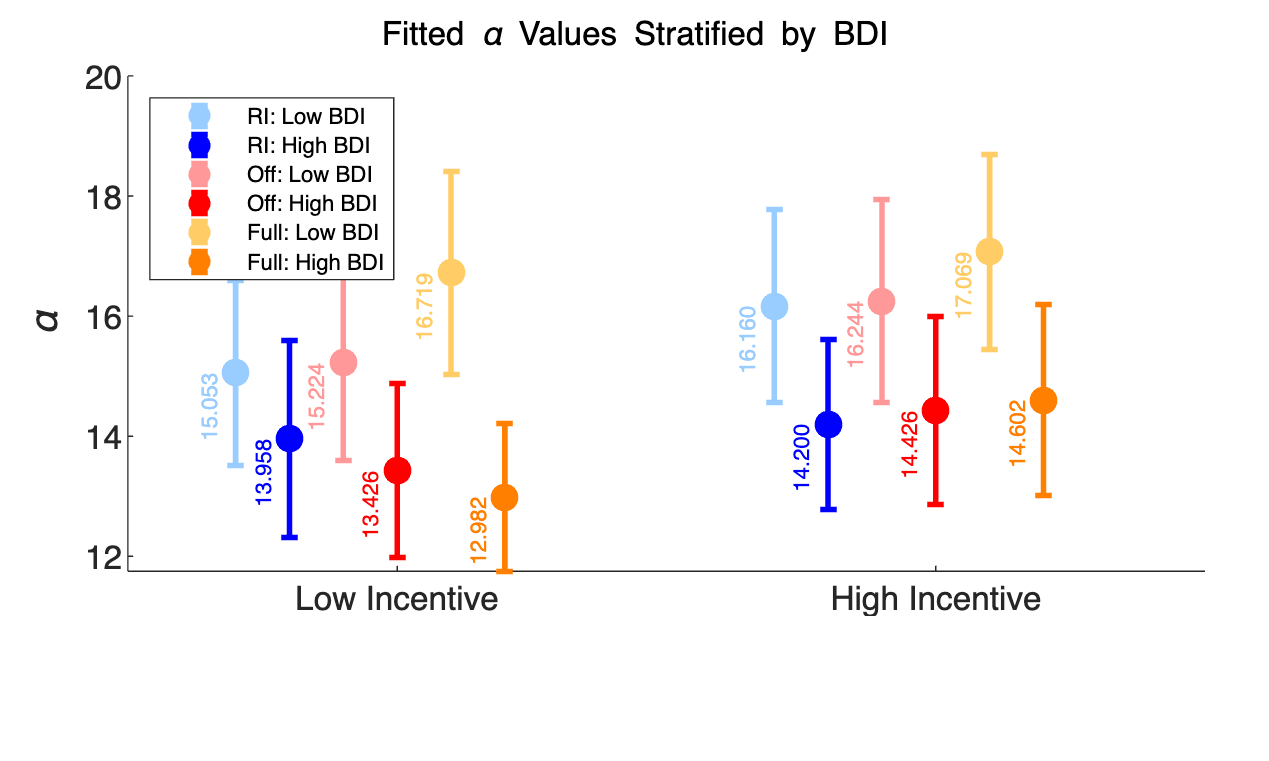

%% Combined Fitted Alpha Plot for All Models

% Define color scheme
light_blue = [0.6, 0.8, 1.0];     % Light blue for RI Low BDI
dark_blue = [0.0, 0.0, 1.0];      % Blue for RI High BDI
light_red = [1.0, 0.6, 0.6];      % Light red for BDI_off Low BDI
dark_red = [1.0, 0.0, 0.0];       % Red for BDI_off High BDI
light_orange = [1.0, 0.8, 0.4];   % Light orange for BDI Full Low BDI
dark_orange = [1.0, 0.5, 0.0];    % Dark orange for BDI Full High BDI

% Common stratification based on BDI
numSubjects = length(scaledBDI);
median_BDI_val = median(scaledBDI);
lowBdiIndices = find(scaledBDI < median_BDI_val);
highBdiIndices = find(scaledBDI >= median_BDI_val);

%% Calculate RI Model Alphas
alpha_low_RI = results_RI.x(:,2);
alpha_high_RI = results_RI.x(:,3);

% RI Model - Low BDI group
RI_alpha_low_lowBDI = mean(alpha_low_RI(lowBdiIndices));
RI_alpha_high_lowBDI = mean(alpha_high_RI(lowBdiIndices));
RI_se_low_lowBDI = std(alpha_low_RI(lowBdiIndices)) / sqrt(length(lowBdiIndices));
RI_se_high_lowBDI = std(alpha_high_RI(lowBdiIndices)) / sqrt(length(lowBdiIndices));

% RI Model - High BDI group
RI_alpha_low_highBDI = mean(alpha_low_RI(highBdiIndices));
RI_alpha_high_highBDI = mean(alpha_high_RI(highBdiIndices));
RI_se_low_highBDI = std(alpha_low_RI(highBdiIndices)) / sqrt(length(highBdiIndices));
RI_se_high_highBDI = std(alpha_high_RI(highBdiIndices)) / sqrt(length(highBdiIndices));

%% Calculate BDI_off Model Alphas
alpha_low_BDI_off = results_BDI_off.x(:,2);
alpha_high_BDI_off = alpha_low_BDI_off + results_BDI_off.x(:,4);

% BDI_off Model - Low BDI group
BDIoff_alpha_low_lowBDI = mean(alpha_low_BDI_off(lowBdiIndices));
BDIoff_alpha_high_lowBDI = mean(alpha_high_BDI_off(lowBdiIndices));
BDIoff_se_low_lowBDI = std(alpha_low_BDI_off(lowBdiIndices)) / sqrt(length(lowBdiIndices));
BDIoff_se_high_lowBDI = std(alpha_high_BDI_off(lowBdiIndices)) / sqrt(length(lowBdiIndices));

% BDI_off Model - High BDI group
BDIoff_alpha_low_highBDI = mean(alpha_low_BDI_off(highBdiIndices));
BDIoff_alpha_high_highBDI = mean(alpha_high_BDI_off(highBdiIndices));
BDIoff_se_low_highBDI = std(alpha_low_BDI_off(highBdiIndices)) / sqrt(length(highBdiIndices));
BDIoff_se_high_highBDI = std(alpha_high_BDI_off(highBdiIndices)) / sqrt(length(highBdiIndices));

%% Calculate BDI_full Model Alphas
numSubjects_full = size(results_BDI_full.x, 1);
subject_BDI_full = BDI(1:numSubjects_full);
alpha_low_BDI_full = results_BDI_full.x(:,2) + results_BDI_full.x(:,3) .* subject_BDI_full;
alpha_high_BDI_full = alpha_low_BDI_full + results_BDI_full.x(:,4);

% Re-stratify for BDI_full (in case different subjects)
median_BDI_full = median(subject_BDI_full);
lowBdiIndices_full = find(subject_BDI_full < median_BDI_full);
highBdiIndices_full = find(subject_BDI_full >= median_BDI_full);

% BDI_full Model - Low BDI group
BDIfull_alpha_low_lowBDI = mean(alpha_low_BDI_full(lowBdiIndices_full));
BDIfull_alpha_high_lowBDI = mean(alpha_high_BDI_full(lowBdiIndices_full));
BDIfull_se_low_lowBDI = std(alpha_low_BDI_full(lowBdiIndices_full)) / sqrt(length(lowBdiIndices_full));
BDIfull_se_high_lowBDI = std(alpha_high_BDI_full(lowBdiIndices_full)) / sqrt(length(lowBdiIndices_full));

% BDI_full Model - High BDI group
BDIfull_alpha_low_highBDI = mean(alpha_low_BDI_full(highBdiIndices_full));
BDIfull_alpha_high_highBDI = mean(alpha_high_BDI_full(highBdiIndices_full));
BDIfull_se_low_highBDI = std(alpha_low_BDI_full(highBdiIndices_full)) / sqrt(length(highBdiIndices_full));
BDIfull_se_high_highBDI = std(alpha_high_BDI_full(highBdiIndices_full)) / sqrt(length(highBdiIndices_full));

%% Create Combined Plot
figure('Position', [100, 100, 1000, 600]);
subplot('Position', [0.1, 0.25, 0.85, 0.65]);
hold on;

% RI Model positions
h1 = errorbar([0.7, 1.7], [RI_alpha_low_lowBDI, RI_alpha_high_lowBDI], [RI_se_low_lowBDI, RI_se_high_lowBDI], ...
    'o', 'Color', light_blue, 'LineWidth', 2, 'MarkerFaceColor', light_blue, 'MarkerSize', 8, 'LineStyle', 'none');

h2 = errorbar([0.8, 1.8], [RI_alpha_low_highBDI, RI_alpha_high_highBDI], [RI_se_low_highBDI, RI_se_high_highBDI], ...
    'o', 'Color', dark_blue, 'LineWidth', 2, 'MarkerFaceColor', dark_blue, 'MarkerSize', 8, 'LineStyle', 'none');

% BDI_off Model positions
h3 = errorbar([0.9, 1.9], [BDIoff_alpha_low_lowBDI, BDIoff_alpha_high_lowBDI], [BDIoff_se_low_lowBDI, BDIoff_se_high_lowBDI], ...
    'o', 'Color', light_red, 'LineWidth', 2, 'MarkerFaceColor', light_red, 'MarkerSize', 8, 'LineStyle', 'none');

h4 = errorbar([1.0, 2.0], [BDIoff_alpha_low_highBDI, BDIoff_alpha_high_highBDI], [BDIoff_se_low_highBDI, BDIoff_se_high_highBDI], ...
    'o', 'Color', dark_red, 'LineWidth', 2, 'MarkerFaceColor', dark_red, 'MarkerSize', 8, 'LineStyle', 'none');

% BDI_full Model positions
h5 = errorbar([1.1, 2.1], [BDIfull_alpha_low_lowBDI, BDIfull_alpha_high_lowBDI], [BDIfull_se_low_lowBDI, BDIfull_se_high_lowBDI], ...
    'o', 'Color', light_orange, 'LineWidth', 2, 'MarkerFaceColor', light_orange, 'MarkerSize', 8, 'LineStyle', 'none');

h6 = errorbar([1.2, 2.2], [BDIfull_alpha_low_highBDI, BDIfull_alpha_high_highBDI], [BDIfull_se_low_highBDI, BDIfull_se_high_highBDI], ...
    'o', 'Color', dark_orange, 'LineWidth', 2, 'MarkerFaceColor', dark_orange, 'MarkerSize', 8, 'LineStyle', 'none');

% Add value labels
% RI Model labels
text(0.65, RI_alpha_low_lowBDI, sprintf('%.3f', RI_alpha_low_lowBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', light_blue, 'FontSize', 8);
text(1.65, RI_alpha_high_lowBDI, sprintf('%.3f', RI_alpha_high_lowBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', light_blue, 'FontSize', 8);
text(0.75, RI_alpha_low_highBDI, sprintf('%.3f', RI_alpha_low_highBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', dark_blue, 'FontSize', 8);
text(1.75, RI_alpha_high_highBDI, sprintf('%.3f', RI_alpha_high_highBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', dark_blue, 'FontSize', 8);

% BDI_off Model labels
text(0.85, BDIoff_alpha_low_lowBDI, sprintf('%.3f', BDIoff_alpha_low_lowBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', light_red, 'FontSize', 8);
text(1.85, BDIoff_alpha_high_lowBDI, sprintf('%.3f', BDIoff_alpha_high_lowBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', light_red, 'FontSize', 8);
text(0.95, BDIoff_alpha_low_highBDI, sprintf('%.3f', BDIoff_alpha_low_highBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', dark_red, 'FontSize', 8);
text(1.95, BDIoff_alpha_high_highBDI, sprintf('%.3f', BDIoff_alpha_high_highBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', dark_red, 'FontSize', 8);

% BDI_full Model labels
text(1.05, BDIfull_alpha_low_lowBDI, sprintf('%.3f', BDIfull_alpha_low_lowBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', light_orange, 'FontSize', 8);
text(2.05, BDIfull_alpha_high_lowBDI, sprintf('%.3f', BDIfull_alpha_high_lowBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', light_orange, 'FontSize', 8);
text(1.15, BDIfull_alpha_low_highBDI, sprintf('%.3f', BDIfull_alpha_low_highBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', dark_orange, 'FontSize', 8);
text(2.15, BDIfull_alpha_high_highBDI, sprintf('%.3f', BDIfull_alpha_high_highBDI), 'Rotation', 90, ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle', 'Color', dark_orange, 'FontSize', 8);

% Formatting
xlim([0.5, 2.5]);
set(gca, 'XTick', [1, 2], 'XTickLabel', {'Low Incentive', 'High Incentive'});
set(gca, 'FontSize', 12);
ylabel('\alpha', 'FontSize', 14);
sgtitle('Fitted \alpha Values Stratified by BDI', 'FontSize', 12);

% Create compact legend positioned outside the main plot area
legend([h1, h2, h3, h4, h5, h6], ...
    {'RI: Low BDI', 'RI: High BDI', ...
     'Off: Low BDI', 'Off: High BDI', ...
     'Full: Low BDI', 'Full: High BDI'}, ...
    'Location', 'northwest', 'FontSize', 8)

hold off;

## Alphas as a Function of BDI Scores

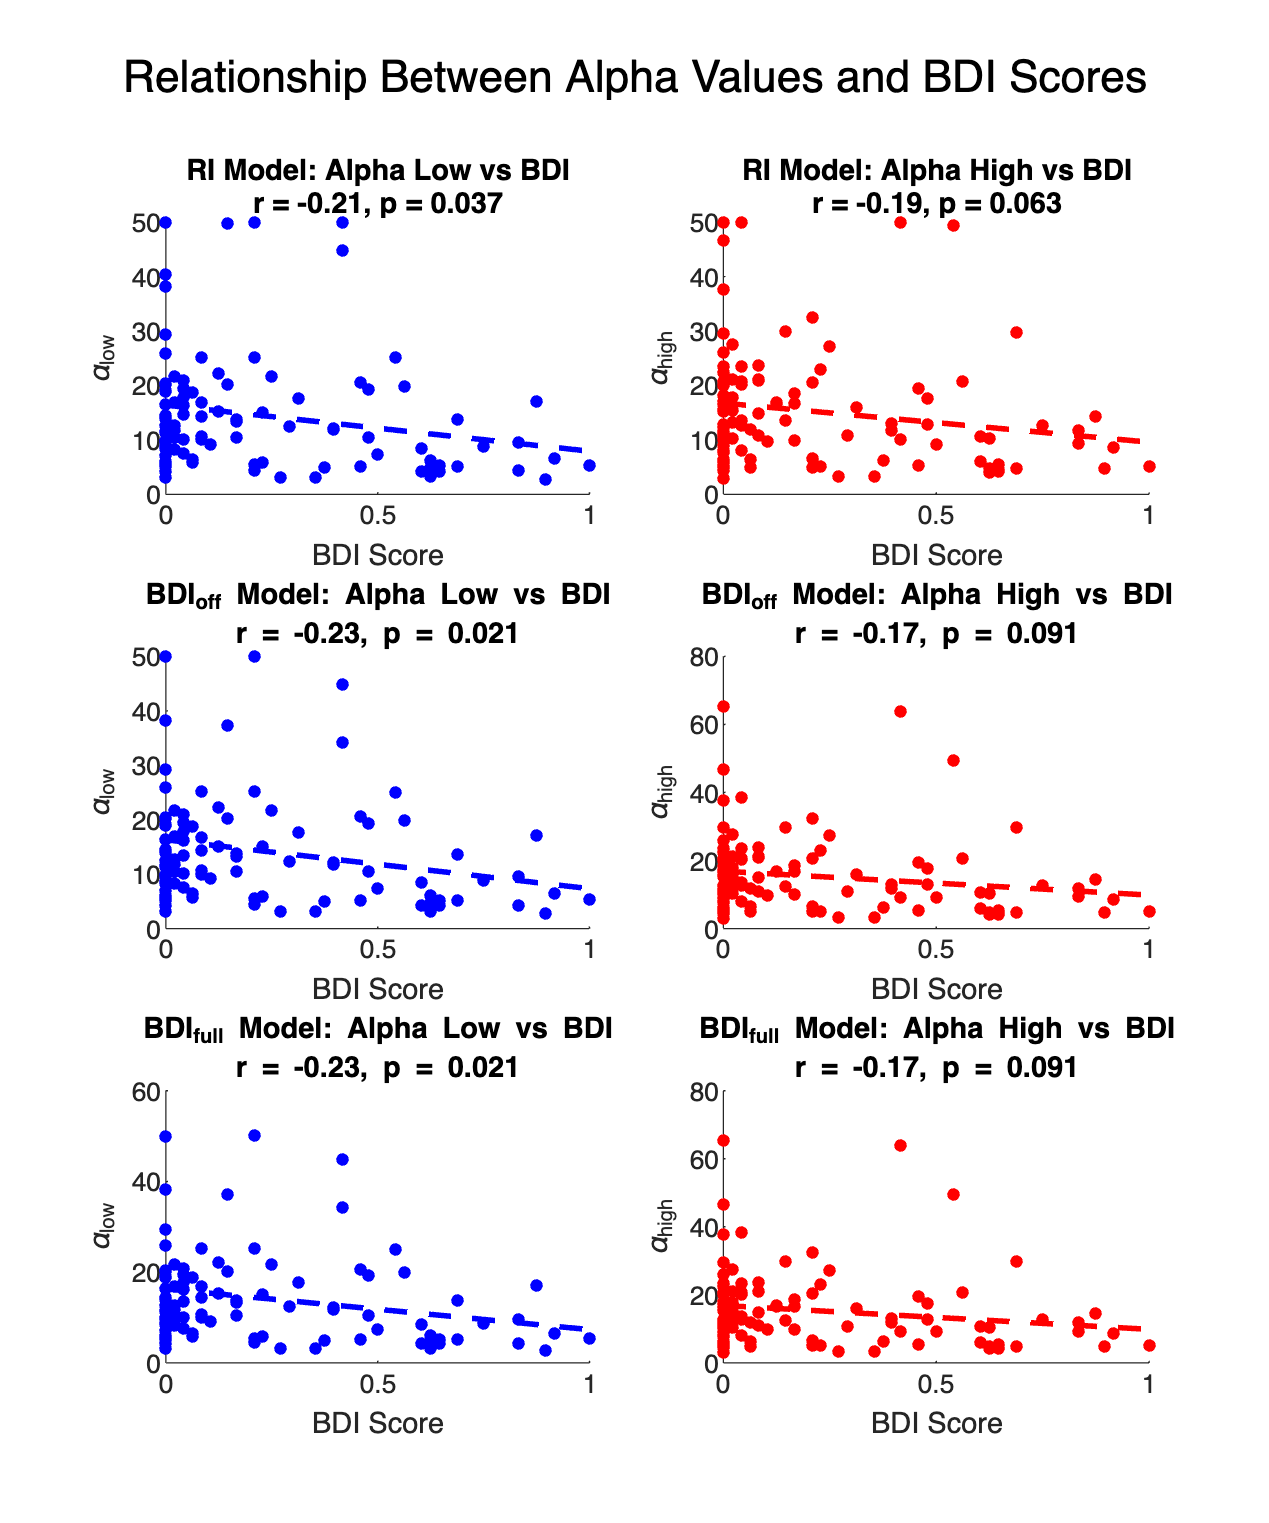

% Create scatter plots of alpha values vs BDI scores for all three models
figure;

% ===== PANEL A: RI MODEL =====
subplot(3,2,1);
scatter(scaledBDI, results_RI.x(:,2), 20, 'b', 'filled');
hold on;
% Add best fit line
p = polyfit(scaledBDI, results_RI.x(:,2), 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'b--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, results_RI.x(:,2), 'rows', 'complete');
title(sprintf('RI Model: Alpha Low vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{low}');

subplot(3,2,2);
scatter(scaledBDI, results_RI.x(:,3), 20, 'r', 'filled');
hold on;
% Add best fit line
p = polyfit(scaledBDI, results_RI.x(:,3), 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, results_RI.x(:,3), 'rows', 'complete');
title(sprintf('RI Model: Alpha High vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{high}');

% ===== PANEL B: BDI_OFF MODEL =====
% For BDI_off model, calculate alpha values
alpha_low_BDI_off = results_BDI_off.x(:,2);
alpha_high_BDI_off = alpha_low_BDI_off + results_BDI_off.x(:,4);

subplot(3,2,3);
scatter(scaledBDI, alpha_low_BDI_off, 20, 'b', 'filled');
hold on;
% Add best fit line
p = polyfit(scaledBDI, alpha_low_BDI_off, 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'b--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, alpha_low_BDI_off, 'rows', 'complete');
title(sprintf('BDI_{off} Model: Alpha Low vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{low}');

subplot(3,2,4);
scatter(scaledBDI, alpha_high_BDI_off, 20, 'r', 'filled');
hold on;
% Add best fit line
p = polyfit(scaledBDI, alpha_high_BDI_off, 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, alpha_high_BDI_off, 'rows', 'complete');
title(sprintf('BDI_{off} Model: Alpha High vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{high}');

% ===== PANEL C: BDI_FULL MODEL =====
% For BDI_full model, calculate alpha values
subject_BDI = scaledBDI;  % Use the same BDI scores
alpha_low_BDI_full = results_BDI_full.x(:,2) + results_BDI_full.x(:,3) .* subject_BDI;
alpha_high_BDI_full = alpha_low_BDI_full + results_BDI_full.x(:,4);

subplot(3,2,5);
scatter(scaledBDI, alpha_low_BDI_full, 20, 'b', 'filled');
hold on;
% Add best fit line
p = polyfit(scaledBDI, alpha_low_BDI_full, 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'b--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, alpha_low_BDI_full, 'rows', 'complete');
title(sprintf('BDI_{full} Model: Alpha Low vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{low}');

subplot(3,2,6);
scatter(scaledBDI, alpha_high_BDI_full, 20, 'r', 'filled');
hold on;
% Add best fit line
p = polyfit(scaledBDI, alpha_high_BDI_full, 1);
x_fit = linspace(min(scaledBDI), max(scaledBDI), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r--', 'LineWidth', 2);
[r, p_val] = corr(scaledBDI, alpha_high_BDI_full, 'rows', 'complete');
title(sprintf('BDI_{full} Model: Alpha High vs BDI\nr = %.2f, p = %.3f', r, p_val));
xlabel('BDI Score');
ylabel('\alpha_{high}');

% Adjust figure size and layout
set(gcf, 'Position', [100, 100, 1000, 1200]);  % Increased height to accommodate the extra row
sgtitle('Relationship Between Alpha Values and BDI Scores', 'FontSize', 16);
hold off;

## Alphas vs. Recovered Alphas

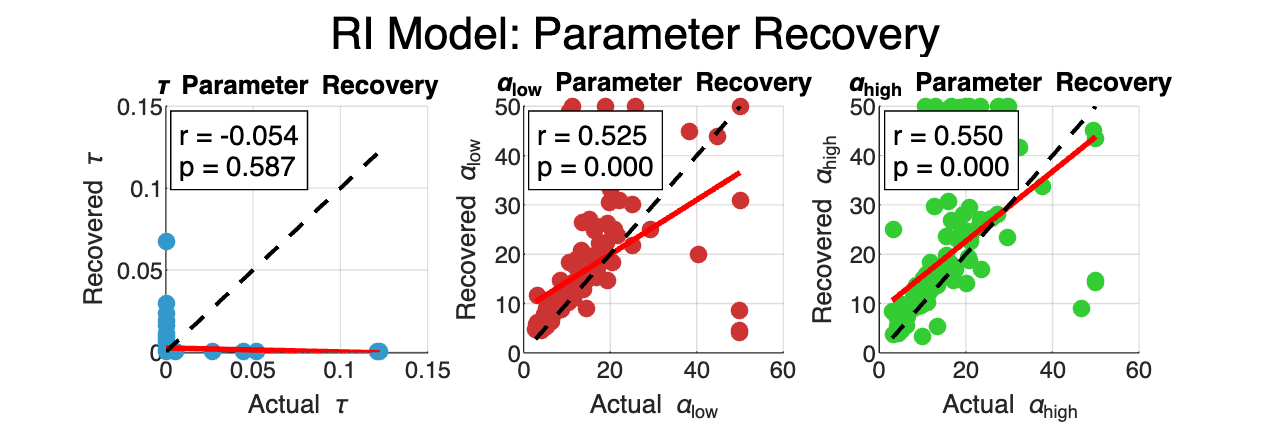

num_subjects = length(data_synth_RI);

% Initialize arrays for RI model parameters
tau_actual_RI = zeros(num_subjects, 1);
alpha_low_actual_RI = zeros(num_subjects, 1);
alpha_high_actual_RI = zeros(num_subjects, 1);

tau_recovered_RI = zeros(num_subjects, 1);
alpha_low_recovered_RI = zeros(num_subjects, 1);
alpha_high_recovered_RI = zeros(num_subjects, 1);

% Extract parameters for RI model
for s = 1:num_subjects
    % Actual parameters (fitted to real data)
    tau_actual_RI(s) = results_RI.x(s, 1);
    alpha_low_actual_RI(s) = results_RI.x(s, 2);
    alpha_high_actual_RI(s) = results_RI.x(s, 3);
    
    % Recovered parameters (fitted to simulated data)
    tau_recovered_RI(s) = results_synth_RI.x(s, 1);
    alpha_low_recovered_RI(s) = results_synth_RI.x(s, 2);
    alpha_high_recovered_RI(s) = results_synth_RI.x(s, 3);
end

% Create RI model recovery plots
figure('Position', [100, 100, 1200, 400]);
sgtitle('RI Model: Parameter Recovery', 'FontSize', 16);

% Tau recovery
subplot(1, 3, 1);
scatter(tau_actual_RI, tau_recovered_RI, 40, 'filled', 'MarkerFaceColor', [0.2, 0.6, 0.8]);
xlabel('Actual \tau');
ylabel('Recovered \tau');
title('\tau Parameter Recovery');
grid on;
hold on;

% Add best fit line
p = polyfit(tau_actual_RI, tau_recovered_RI, 1);
plotrange = linspace(min(tau_actual_RI), max(tau_actual_RI), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);

% Add unity line
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

% Calculate and display correlation
[r, p_val] = corr(tau_actual_RI, tau_recovered_RI, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Alpha_low recovery
subplot(1, 3, 2);
scatter(alpha_low_actual_RI, alpha_low_recovered_RI, 40, 'filled', 'MarkerFaceColor', [0.8, 0.2, 0.2]);
xlabel('Actual \alpha_{low}');
ylabel('Recovered \alpha_{low}');
title('\alpha_{low} Parameter Recovery');
grid on;
hold on;

p = polyfit(alpha_low_actual_RI, alpha_low_recovered_RI, 1);
plotrange = linspace(min(alpha_low_actual_RI), max(alpha_low_actual_RI), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(alpha_low_actual_RI, alpha_low_recovered_RI, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Alpha_high recovery
subplot(1, 3, 3);
scatter(alpha_high_actual_RI, alpha_high_recovered_RI, 40, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
xlabel('Actual \alpha_{high}');
ylabel('Recovered \alpha_{high}');
title('\alpha_{high} Parameter Recovery');
grid on;
hold on;

p = polyfit(alpha_high_actual_RI, alpha_high_recovered_RI, 1);
plotrange = linspace(min(alpha_high_actual_RI), max(alpha_high_actual_RI), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(alpha_high_actual_RI, alpha_high_recovered_RI, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

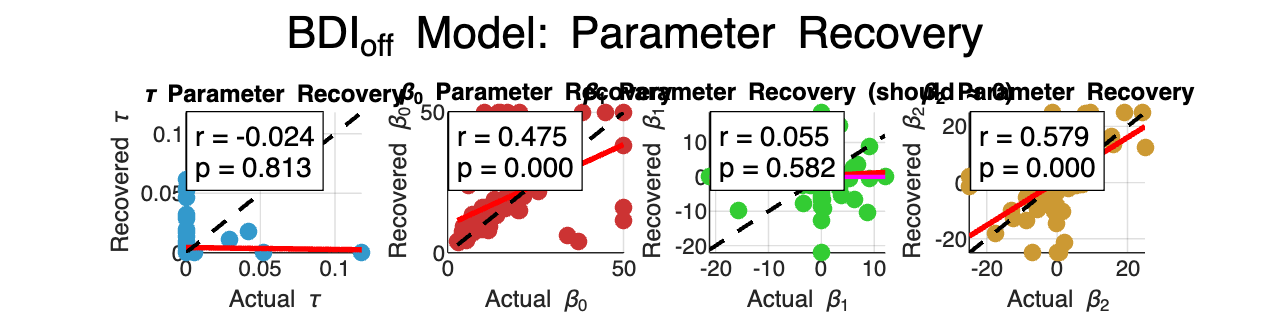


%% ================================
%% BDI_OFF MODEL PARAMETER RECOVERY
%% ================================

num_subjects_bdi_off = length(data_synth_BDI_off);

% Initialize arrays for BDI_off model parameters
tau_actual_BDI_off = zeros(num_subjects_bdi_off, 1);
beta0_actual_BDI_off = zeros(num_subjects_bdi_off, 1);
beta1_actual_BDI_off = zeros(num_subjects_bdi_off, 1);
beta2_actual_BDI_off = zeros(num_subjects_bdi_off, 1);

tau_recovered_BDI_off = zeros(num_subjects_bdi_off, 1);
beta0_recovered_BDI_off = zeros(num_subjects_bdi_off, 1);
beta1_recovered_BDI_off = zeros(num_subjects_bdi_off, 1);
beta2_recovered_BDI_off = zeros(num_subjects_bdi_off, 1);

% Extract parameters for BDI_off model
for s = 1:num_subjects_bdi_off
    % Actual parameters
    tau_actual_BDI_off(s) = results_BDI_off.x(s, 1);
    beta0_actual_BDI_off(s) = results_BDI_off.x(s, 2);
    beta1_actual_BDI_off(s) = results_BDI_off.x(s, 3);
    beta2_actual_BDI_off(s) = results_BDI_off.x(s, 4);
    
    % Recovered parameters
    tau_recovered_BDI_off(s) = results_synth_BDI_off.x(s, 1);
    beta0_recovered_BDI_off(s) = results_synth_BDI_off.x(s, 2);
    beta1_recovered_BDI_off(s) = results_synth_BDI_off.x(s, 3);
    beta2_recovered_BDI_off(s) = results_synth_BDI_off.x(s, 4);
end

% Create BDI_off model recovery plots
figure('Position', [100, 150, 1600, 400]);
sgtitle('BDI_{off} Model: Parameter Recovery', 'FontSize', 16);

% Tau recovery
subplot(1, 4, 1);
scatter(tau_actual_BDI_off, tau_recovered_BDI_off, 40, 'filled', 'MarkerFaceColor', [0.2, 0.6, 0.8]);
xlabel('Actual \tau');
ylabel('Recovered \tau');
title('\tau Parameter Recovery');
grid on;
hold on;

p = polyfit(tau_actual_BDI_off, tau_recovered_BDI_off, 1);
plotrange = linspace(min(tau_actual_BDI_off), max(tau_actual_BDI_off), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(tau_actual_BDI_off, tau_recovered_BDI_off, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Beta0 recovery
subplot(1, 4, 2);
scatter(beta0_actual_BDI_off, beta0_recovered_BDI_off, 40, 'filled', 'MarkerFaceColor', [0.8, 0.2, 0.2]);
xlabel('Actual \beta_0');
ylabel('Recovered \beta_0');
title('\beta_0 Parameter Recovery');
grid on;
hold on;

p = polyfit(beta0_actual_BDI_off, beta0_recovered_BDI_off, 1);
plotrange = linspace(min(beta0_actual_BDI_off), max(beta0_actual_BDI_off), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(beta0_actual_BDI_off, beta0_recovered_BDI_off, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Beta1 recovery (should be near zero for BDI_off)
subplot(1, 4, 3);
scatter(beta1_actual_BDI_off, beta1_recovered_BDI_off, 40, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
xlabel('Actual \beta_1');
ylabel('Recovered \beta_1');
title('\beta_1 Parameter Recovery (should ≈ 0)');
grid on;
hold on;

p = polyfit(beta1_actual_BDI_off, beta1_recovered_BDI_off, 1);
plotrange = linspace(min(beta1_actual_BDI_off), max(beta1_actual_BDI_off), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);
% Add horizontal line at zero
plot([min(beta1_actual_BDI_off), max(beta1_actual_BDI_off)], [0, 0], 'm-', 'LineWidth', 1.5);

[r, p_val] = corr(beta1_actual_BDI_off, beta1_recovered_BDI_off, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Beta2 recovery
subplot(1, 4, 4);
scatter(beta2_actual_BDI_off, beta2_recovered_BDI_off, 40, 'filled', 'MarkerFaceColor', [0.8, 0.6, 0.2]);
xlabel('Actual \beta_2');
ylabel('Recovered \beta_2');
title('\beta_2 Parameter Recovery');
grid on;
hold on;

p = polyfit(beta2_actual_BDI_off, beta2_recovered_BDI_off, 1);
plotrange = linspace(min(beta2_actual_BDI_off), max(beta2_actual_BDI_off), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(beta2_actual_BDI_off, beta2_recovered_BDI_off, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

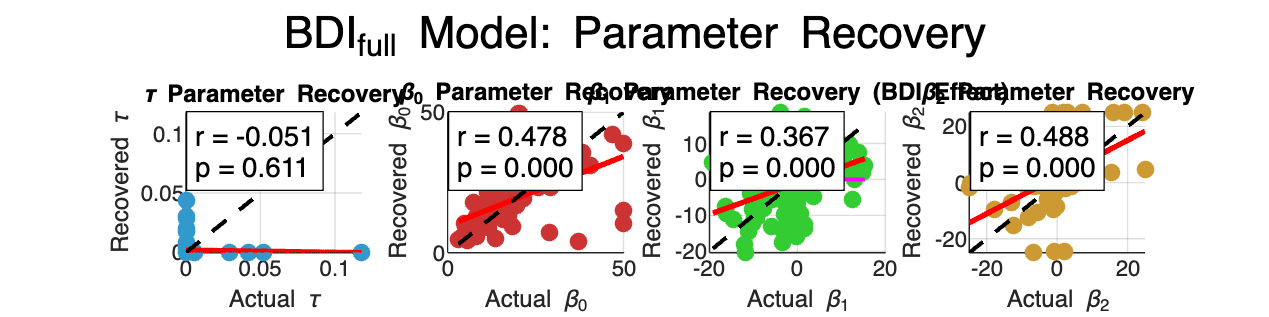


%% ================================
%% BDI_FULL MODEL PARAMETER RECOVERY
%% ================================

num_subjects_bdi_full = length(data_synth_BDI_full);

% Initialize arrays for BDI_full model parameters
tau_actual_BDI_full = zeros(num_subjects_bdi_full, 1);
beta0_actual_BDI_full = zeros(num_subjects_bdi_full, 1);
beta1_actual_BDI_full = zeros(num_subjects_bdi_full, 1);
beta2_actual_BDI_full = zeros(num_subjects_bdi_full, 1);

tau_recovered_BDI_full = zeros(num_subjects_bdi_full, 1);
beta0_recovered_BDI_full = zeros(num_subjects_bdi_full, 1);
beta1_recovered_BDI_full = zeros(num_subjects_bdi_full, 1);
beta2_recovered_BDI_full = zeros(num_subjects_bdi_full, 1);

% Extract parameters for BDI_full model
for s = 1:num_subjects_bdi_full
    % Actual parameters
    tau_actual_BDI_full(s) = results_BDI_full.x(s, 1);
    beta0_actual_BDI_full(s) = results_BDI_full.x(s, 2);
    beta1_actual_BDI_full(s) = results_BDI_full.x(s, 3);
    beta2_actual_BDI_full(s) = results_BDI_full.x(s, 4);
    
    % Recovered parameters
    tau_recovered_BDI_full(s) = results_synth_BDI_full.x(s, 1);
    beta0_recovered_BDI_full(s) = results_synth_BDI_full.x(s, 2);
    beta1_recovered_BDI_full(s) = results_synth_BDI_full.x(s, 3);
    beta2_recovered_BDI_full(s) = results_synth_BDI_full.x(s, 4);
end

% Create BDI_full model recovery plots
figure('Position', [100, 200, 1600, 400]);
sgtitle('BDI_{full} Model: Parameter Recovery', 'FontSize', 16);

% Tau recovery
subplot(1, 4, 1);
scatter(tau_actual_BDI_full, tau_recovered_BDI_full, 40, 'filled', 'MarkerFaceColor', [0.2, 0.6, 0.8]);
xlabel('Actual \tau');
ylabel('Recovered \tau');
title('\tau Parameter Recovery');
grid on;
hold on;

p = polyfit(tau_actual_BDI_full, tau_recovered_BDI_full, 1);
plotrange = linspace(min(tau_actual_BDI_full), max(tau_actual_BDI_full), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(tau_actual_BDI_full, tau_recovered_BDI_full, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Beta0 recovery
subplot(1, 4, 2);
scatter(beta0_actual_BDI_full, beta0_recovered_BDI_full, 40, 'filled', 'MarkerFaceColor', [0.8, 0.2, 0.2]);
xlabel('Actual \beta_0');
ylabel('Recovered \beta_0');
title('\beta_0 Parameter Recovery');
grid on;
hold on;

p = polyfit(beta0_actual_BDI_full, beta0_recovered_BDI_full, 1);
plotrange = linspace(min(beta0_actual_BDI_full), max(beta0_actual_BDI_full), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(beta0_actual_BDI_full, beta0_recovered_BDI_full, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Beta1 recovery (BDI effect)
subplot(1, 4, 3);
scatter(beta1_actual_BDI_full, beta1_recovered_BDI_full, 40, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
xlabel('Actual \beta_1');
ylabel('Recovered \beta_1');
title('\beta_1 Parameter Recovery (BDI Effect)');
grid on;
hold on;

p = polyfit(beta1_actual_BDI_full, beta1_recovered_BDI_full, 1);
plotrange = linspace(min(beta1_actual_BDI_full), max(beta1_actual_BDI_full), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);
% Add horizontal line at zero for reference
plot([min(beta1_actual_BDI_full), max(beta1_actual_BDI_full)], [0, 0], 'm-', 'LineWidth', 1.5);

[r, p_val] = corr(beta1_actual_BDI_full, beta1_recovered_BDI_full, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;

% Beta2 recovery
subplot(1, 4, 4);
scatter(beta2_actual_BDI_full, beta2_recovered_BDI_full, 40, 'filled', 'MarkerFaceColor', [0.8, 0.6, 0.2]);
xlabel('Actual \beta_2');
ylabel('Recovered \beta_2');
title('\beta_2 Parameter Recovery');
grid on;
hold on;

p = polyfit(beta2_actual_BDI_full, beta2_recovered_BDI_full, 1);
plotrange = linspace(min(beta2_actual_BDI_full), max(beta2_actual_BDI_full), 100);
plot(plotrange, polyval(p, plotrange), 'r-', 'LineWidth', 2);
plot(plotrange, plotrange, 'k--', 'LineWidth', 1.5);

[r, p_val] = corr(beta2_actual_BDI_full, beta2_recovered_BDI_full, 'rows', 'complete');
text(0.05, 0.95, sprintf('r = %.3f\np = %.3f', r, p_val), ...
    'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 10, ...
    'BackgroundColor', 'white', 'EdgeColor', 'black');
hold off;


%% ================================
%% SUMMARY STATISTICS
%% ================================

fprintf('\n=== PARAMETER RECOVERY SUMMARY ===\n');


=== PARAMETER RECOVERY SUMMARY ===



fprintf('\n--- RI Model ---\n');


--- RI Model ---


fprintf('Tau:        r = %.3f, p = %.3f\n', corr(tau_actual_RI, tau_recovered_RI));

Tau:        r = -0.054, p = 

fprintf('Alpha_low:  r = %.3f, p = %.3f\n', corr(alpha_low_actual_RI, alpha_low_recovered_RI));

Alpha_low:  r = 0.525, p = 

fprintf('Alpha_high: r = %.3f, p = %.3f\n', corr(alpha_high_actual_RI, alpha_high_recovered_RI));

Alpha_high: r = 0.550, p = 


fprintf('\n--- BDI_off Model ---\n');


--- BDI_off Model ---


fprintf('Tau:   r = %.3f, p = %.3f\n', corr(tau_actual_BDI_off, tau_recovered_BDI_off));

Tau:   r = -0.024, p = 

fprintf('Beta0: r = %.3f, p = %.3f\n', corr(beta0_actual_BDI_off, beta0_recovered_BDI_off));

Beta0: r = 0.475, p = 

fprintf('Beta1: r = %.3f, p = %.3f (should be near 0)\n', corr(beta1_actual_BDI_off, beta1_recovered_BDI_off));

Beta1: r = 0.055, p = 

fprintf('Beta2: r = %.3f, p = %.3f\n', corr(beta2_actual_BDI_off, beta2_recovered_BDI_off));

Beta2: r = 0.579, p = 


fprintf('\n--- BDI_full Model ---\n');


--- BDI_full Model ---


fprintf('Tau:   r = %.3f, p = %.3f\n', corr(tau_actual_BDI_full, tau_recovered_BDI_full));

Tau:   r = -0.051, p = 

fprintf('Beta0: r = %.3f, p = %.3f\n', corr(beta0_actual_BDI_full, beta0_recovered_BDI_full));

Beta0: r = 0.478, p = 

fprintf('Beta1: r = %.3f, p = %.3f (BDI effect)\n', corr(beta1_actual_BDI_full, beta1_recovered_BDI_full));

Beta1: r = 0.367, p = 

fprintf('Beta2: r = %.3f, p = %.3f\n', corr(beta2_actual_BDI_full, beta2_recovered_BDI_full));

Beta2: r = 0.488, p = 


fprintf('\n--- Parameter Recovery Quality Interpretation ---\n');


--- Parameter Recovery Quality Interpretation ---


fprintf('r > 0.8: Excellent recovery\n');

r > 0.8: Excellent recovery


fprintf('r > 0.6: Good recovery\n');

r > 0.6: Good recovery


fprintf('r > 0.4: Moderate recovery\n');

r > 0.4: Moderate recovery


fprintf('r < 0.4: Poor recovery\n');

r < 0.4: Poor recovery



% Calculate mean absolute error for each parameter
fprintf('\n--- Mean Absolute Errors ---\n');


--- Mean Absolute Errors ---


fprintf('\nRI Model:\n');


RI Model:


fprintf('Tau MAE:        %.4f\n', mean(abs(tau_actual_RI - tau_recovered_RI)));

Tau MAE:        0.0059


fprintf('Alpha_low MAE:  %.4f\n', mean(abs(alpha_low_actual_RI - alpha_low_recovered_RI)));

Alpha_low MAE:  6.2301


fprintf('Alpha_high MAE: %.4f\n', mean(abs(alpha_high_actual_RI - alpha_high_recovered_RI)));

Alpha_high MAE: 7.3334



fprintf('\nBDI_off Model:\n');


BDI_off Model:


fprintf('Tau MAE:   %.4f\n', mean(abs(tau_actual_BDI_off - tau_recovered_BDI_off)));

Tau MAE:   0.0073


fprintf('Beta0 MAE: %.4f\n', mean(abs(beta0_actual_BDI_off - beta0_recovered_BDI_off)));

Beta0 MAE: 7.2960


fprintf('Beta1 MAE: %.4f\n', mean(abs(beta1_actual_BDI_off - beta1_recovered_BDI_off)));

Beta1 MAE: 4.5504


fprintf('Beta2 MAE: %.4f\n', mean(abs(beta2_actual_BDI_off - beta2_recovered_BDI_off)));

Beta2 MAE: 5.0564



fprintf('\nBDI_full Model:\n');


BDI_full Model:


fprintf('Tau MAE:   %.4f\n', mean(abs(tau_actual_BDI_full - tau_recovered_BDI_full)));

Tau MAE:   0.0053


fprintf('Beta0 MAE: %.4f\n', mean(abs(beta0_actual_BDI_full - beta0_recovered_BDI_full)));

Beta0 MAE: 5.9421


fprintf('Beta1 MAE: %.4f\n', mean(abs(beta1_actual_BDI_full - beta1_recovered_BDI_full)));

Beta1 MAE: 6.5718


fprintf('Beta2 MAE: %.4f\n', mean(abs(beta2_actual_BDI_full - beta2_recovered_BDI_full)));

Beta2 MAE: 5.6053



fprintf('\n=== PARAMETER RECOVERY ANALYSIS COMPLETE ===\n');


=== PARAMETER RECOVERY ANALYSIS COMPLETE ===
